% Tensor Component Analysis (TCA): 
clear;

if exist('H:\', 'dir')  % If H:\ exists, assume this is Computer 1
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\BLA';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';

elseif exist('G:\', 'dir')  % If G:\ exists, assume this is Computer 2
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\BLA';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end

% - First prototype the pipeline for BLA (baseline auditory condidtion) for
% the first subject. 
% - Import .set file
condition = ['BLA'];
file_path = fullfile(input_path,'binepochs filtered ICArej BLAAvgBOS2.set');
EEG = pop_loadset(file_path);

pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


fs = EEG.srate; % Sampling rate
time_vector = linspace(-0.5, 3, size(EEG.data, 2)); % Time axis (-500ms to 3000ms)

% - Bandpass filter different EEG bands (theta, alpha, beta, gamma): Here
% we will first focus on beta for its role in attention.
epoch_trials = 1:2:EEG.trials; % Select odd trials
num_trials = length(epoch_trials);

data = EEG.data(:, :, epoch_trials);

% Bandpass filter beta band (13-30 Hz)
beta_band = [13 30];
beta_signal = zeros(size(data)); % Preallocate
for epoch = 1:size(data, 3)
    beta_signal(:,:,epoch) = bandpass(data(:,:,epoch)', beta_band, fs)'; % ch x time x trial
end

% Define pre- and post-stimulus time windows (400ms before and after stimulus onset at 1020ms)
% 512 sample/sec x 0.4 sec = 204.8
% Load trial numbers from Excel file


% Define pre-stimulus window (same for both conditions)
pre_window = [-0.4, 0];
post_window = [0, 0.4];

% % Convert time to indices
pre_idx = find(time_vector >= pre_window(1) & time_vector <= pre_window(2));
post_idx = find(time_vector >= post_window(1) & time_vector <= post_window(2));

% TCA on pre-stimulus window
pre_data = beta_signal(:, pre_idx,:); % ch x time x trial

%[U_pre,output_pre] = cpd(pre_data, 60);

% TCA on post-stimulus window
post_data = beta_signal(:, post_idx,:); % ch x time x trial

%[U_post,output_post] = cpd(post_data, 60);

% Define the range of components to test
num_components = 1:50;  % Test 1 to 50 components
reconstruction_errors_pre = zeros(size(num_components));
explained_variance_pre = zeros(size(num_components));
reconstruction_errors_post = zeros(size(num_components));
explained_variance_post = zeros(size(num_components));

if isempty(gcp('nocreate'))
    parpool; % Uses default number of workers
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.




parfor idx = 1:length(num_components)
    k = num_components(idx);

    [U_pre, ~] = cpd(pre_data, k, 'Display', 0);
    reconstructed_pre = cpdgen(U_pre);
    error_pre = norm(pre_data(:) - reconstructed_pre(:)) / norm(pre_data(:));
    reconstruction_errors_pre(idx) = error_pre;
    explained_variance_pre(idx) = 1 - error_pre^2;

    [U_post, ~] = cpd(post_data, k, 'Display', 0);
    reconstructed_post = cpdgen(U_post);
    error_post = norm(post_data(:) - reconstructed_post(:)) / norm(post_data(:));
    reconstruction_errors_post(idx) = error_post;
    explained_variance_post(idx) = 1 - error_post^2;
end


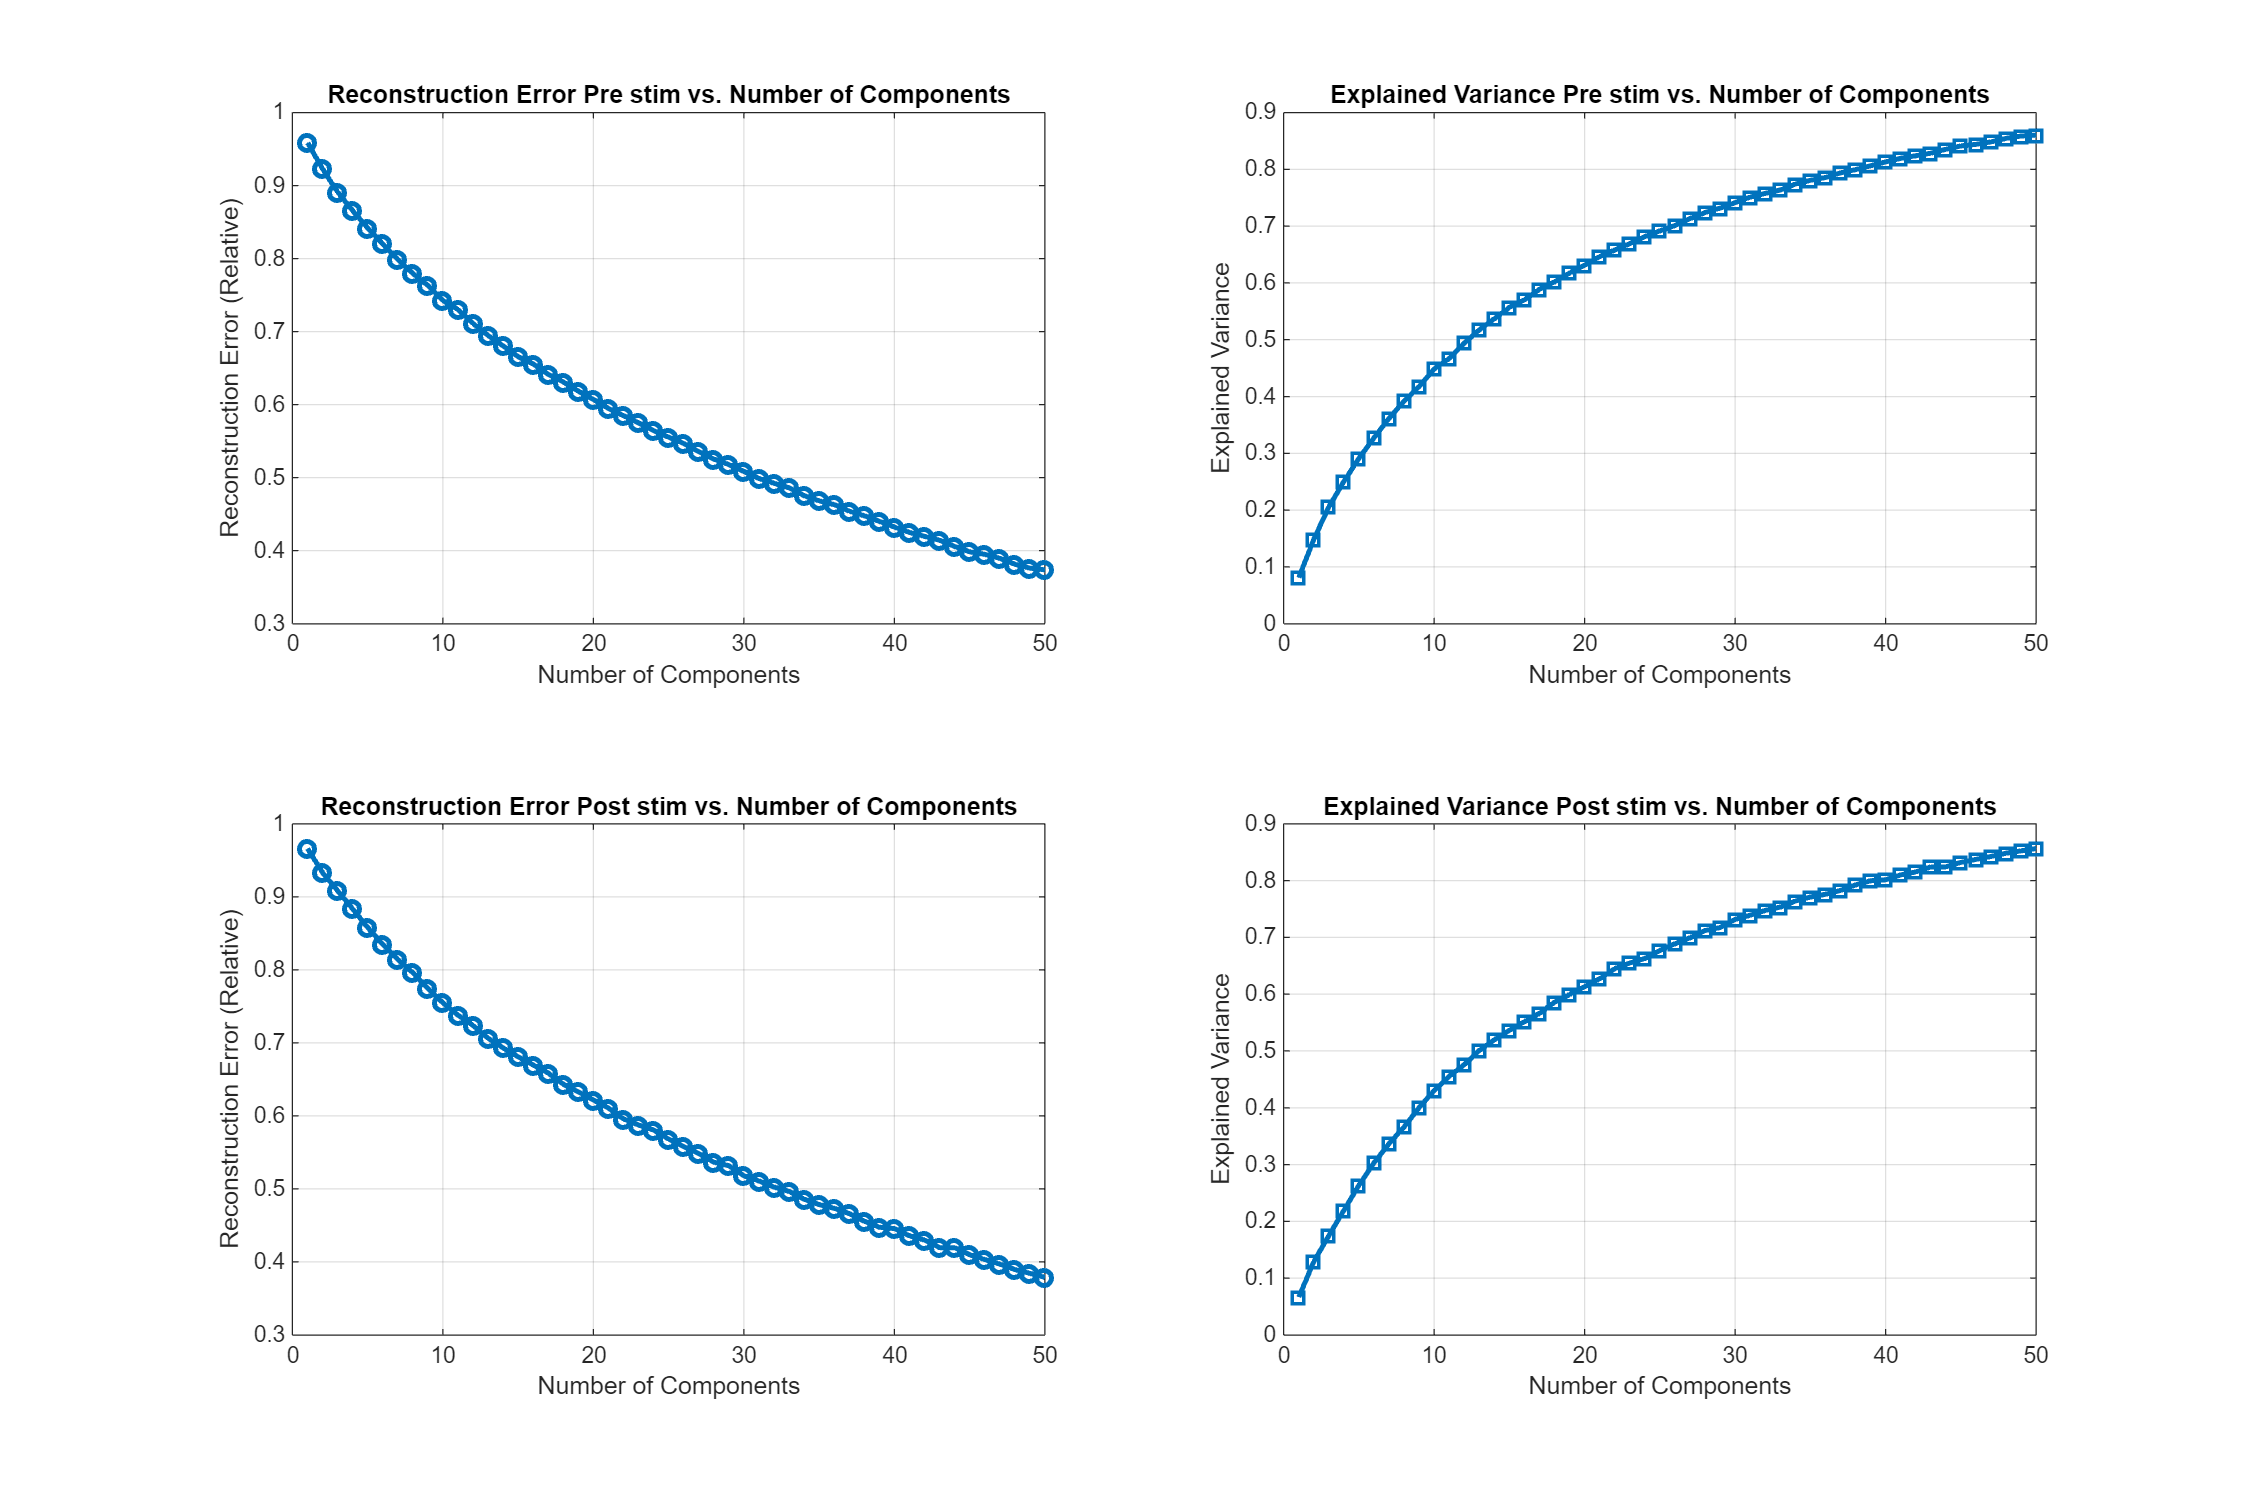

% Plot reconstruction error
figure('Position', [100, 100, 1500, 1000]); % [x, y, width, height]
subplot(2,2,1)
plot(num_components, reconstruction_errors_pre, 'o-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Reconstruction Error (Relative)');
title('Reconstruction Error Pre stim vs. Number of Components');
grid on;

% Plot explained variance
subplot(2,2,2)
plot(num_components, explained_variance_pre, 's-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Explained Variance');
title('Explained Variance Pre stim vs. Number of Components');
grid on;

subplot(2,2,3)
plot(num_components, reconstruction_errors_post, 'o-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Reconstruction Error (Relative)');
title('Reconstruction Error Post stim vs. Number of Components');
grid on;

% Plot explained variance
subplot(2,2,4)
plot(num_components, explained_variance_post, 's-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Explained Variance');
title('Explained Variance Post stim vs. Number of Components');
grid on;

threshold = 0.85;  % Target explained variance threshold

% Preallocate result
pc_at_85_pre = zeros(1, 1);
pc_at_85_post = zeros(1, 1);

pc_at_85_pre = find(round(explained_variance_pre,2) >= threshold, 1, 'first');
pc_at_85_post = find(round(explained_variance_post,2) >= threshold, 1, 'first'); 




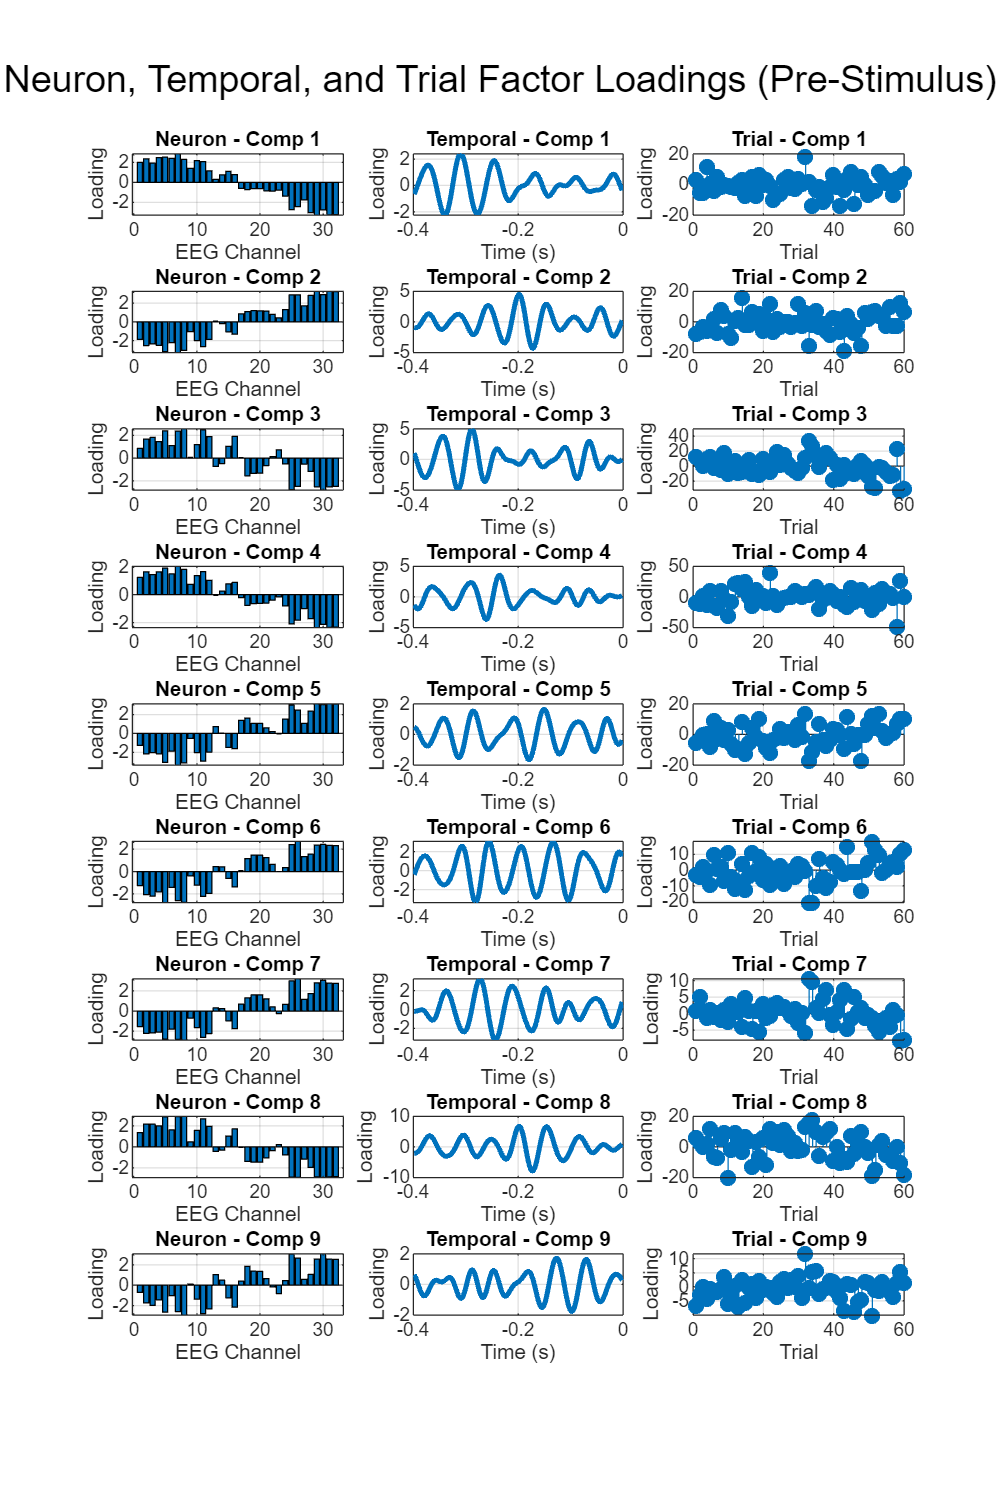

% Chosing to do TCA on the first 46 components since they explain 85% of
% the variance
[U_pre,output_pre ] = cpd(pre_data, pc_at_85_pre);

figure('Position', [100, 100, 1200, 1800]);  % Adjust size for vertical layout

for comp = 1:9
    row = comp;

    % Neuron factor (Column 1)
    subplot(9, 3, (row - 1)*3 + 1);
    bar(U_pre{1}(:, comp));
    title(['Neuron - Comp ' num2str(comp)]);
    xlabel('EEG Channel');
    ylabel('Loading');
    grid on;

    % Temporal factor (Column 2)
    subplot(9, 3, (row - 1)*3 + 2);
    plot(time_vector(pre_idx), U_pre{2}(:, comp), 'LineWidth', 2);
    title(['Temporal - Comp ' num2str(comp)]);
    xlabel('Time (s)');
    ylabel('Loading');
    grid on;

    % Trial factor (Column 3)
    subplot(9, 3, (row - 1)*3 + 3);
    stem(U_pre{3}(:, comp), 'filled');
    title(['Trial - Comp ' num2str(comp)]);
    xlabel('Trial');
    ylabel('Loading');
    grid on;
end

sgtitle('Neuron, Temporal, and Trial Factor Loadings (Pre-Stimulus)');

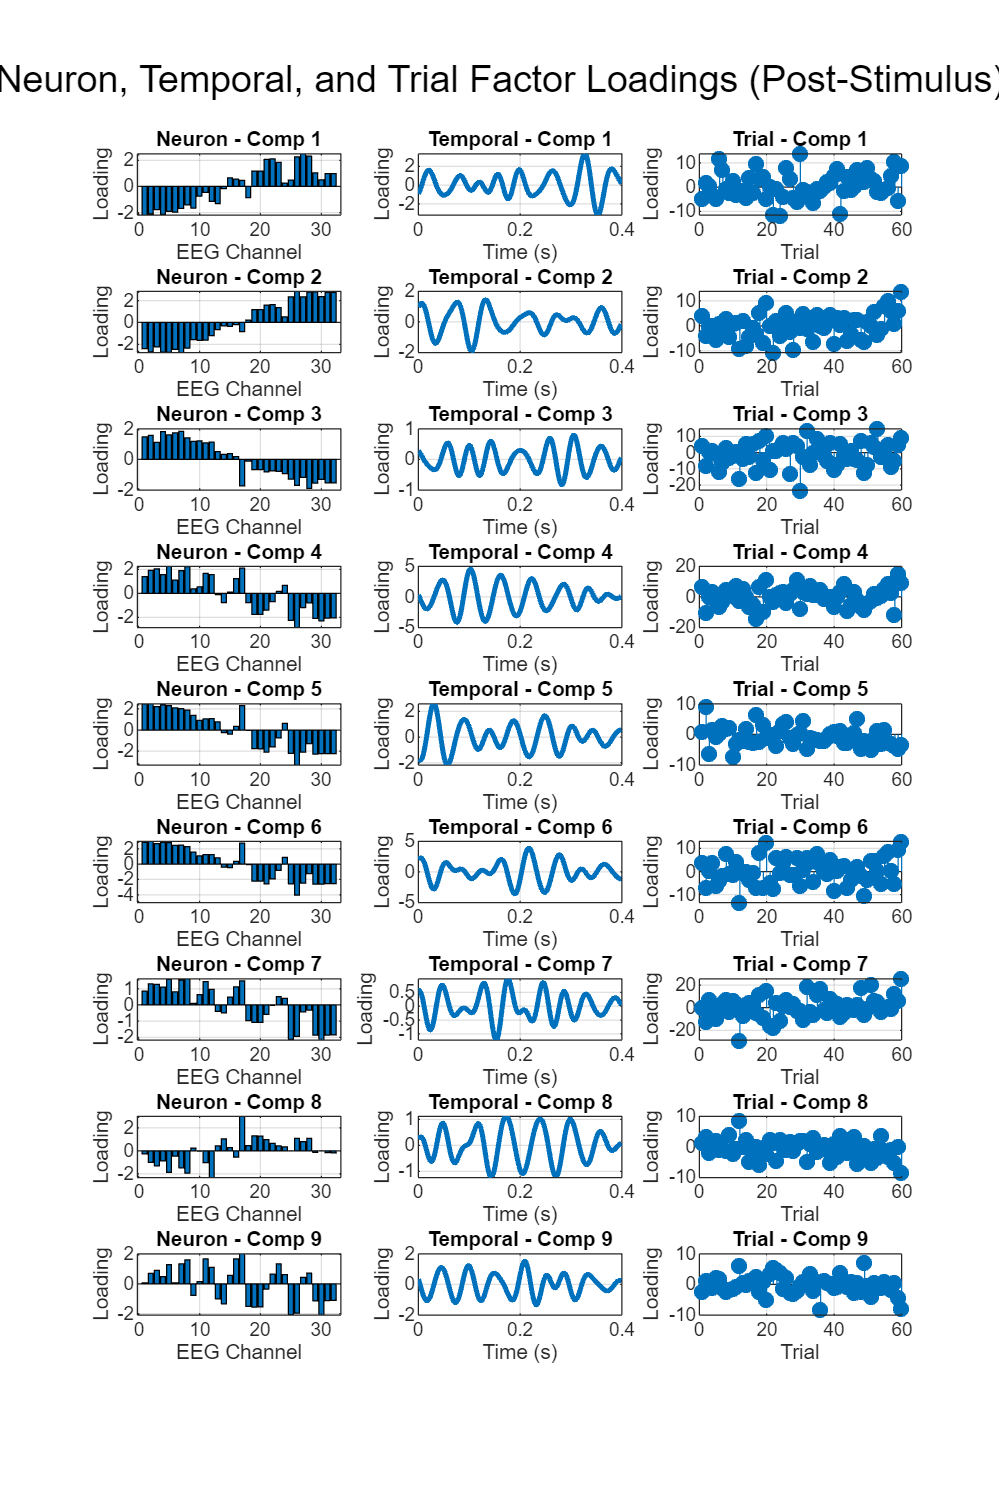


% Chosing to do TCA on the first 48 components since they explain 85% of
% the variance for post stimulus
[U_post,output_post ] = cpd(post_data, pc_at_85_post);
figure('Position', [100, 100, 1200, 1800]);  % Adjust size for vertical layout

for comp = 1:9
    row = comp;

    % Neuron factor (Column 1)
    subplot(9, 3, (row - 1)*3 + 1);
    bar(U_post{1}(:, comp));
    title(['Neuron - Comp ' num2str(comp)]);
    xlabel('EEG Channel');
    ylabel('Loading');
    grid on;

    % Temporal factor (Column 2)
    subplot(9, 3, (row - 1)*3 + 2);
    plot(time_vector(post_idx), U_post{2}(:, comp), 'LineWidth', 2);
    title(['Temporal - Comp ' num2str(comp)]);
    xlabel('Time (s)');
    ylabel('Loading');
    grid on;

    % Trial factor (Column 3)
    subplot(9, 3, (row - 1)*3 + 3);
    stem(U_post{3}(:, comp), 'filled');
    title(['Trial - Comp ' num2str(comp)]);
    xlabel('Trial');
    ylabel('Loading');
    grid on;
end

sgtitle('Neuron, Temporal, and Trial Factor Loadings (Post-Stimulus)');

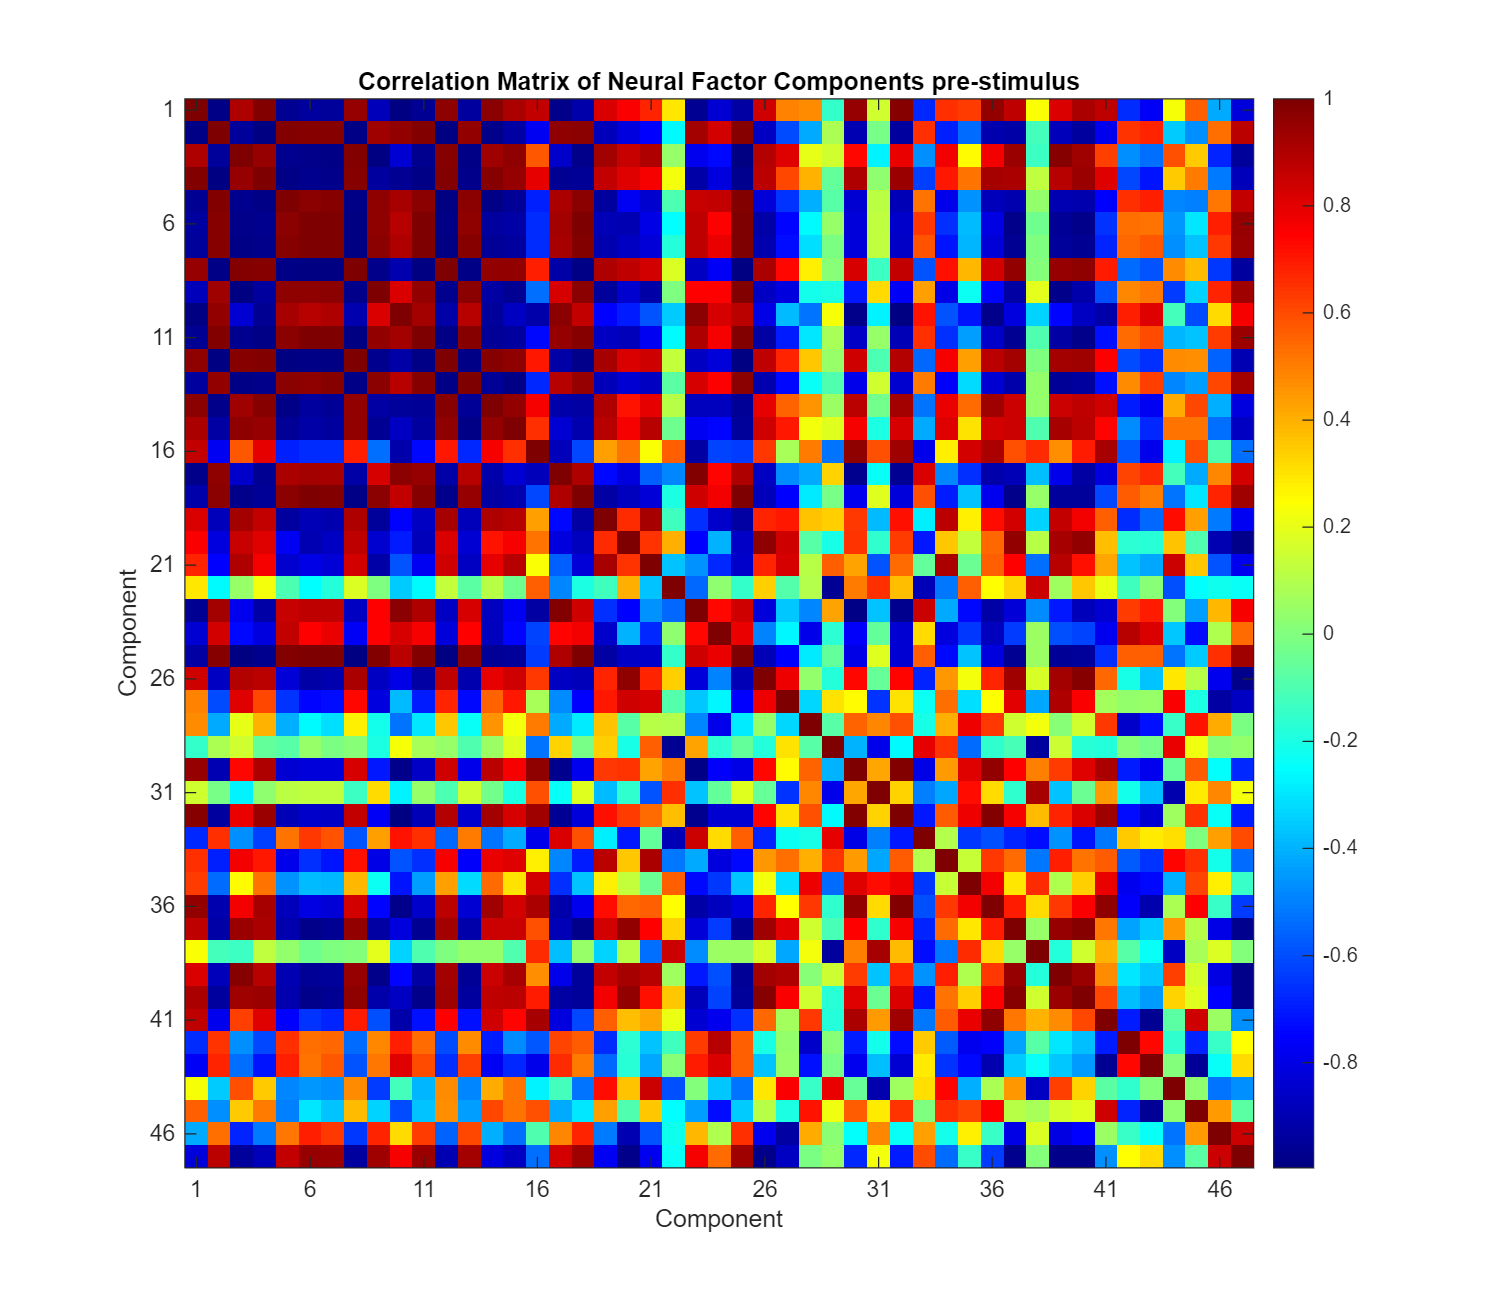

% Factor Analysis: The neuron factor correlation matrix

% Create correlation matrix for neural factor U_post{1}
% Each column in U_post{1} represents a component, so we compute correlations between components
correlation_matrix_pre = corrcoef(U_pre{1});

% Plot the correlation matrix
figure('Position', [100, 100, 800, 700]);
imagesc(correlation_matrix_pre);
colormap('jet');
colorbar;
axis square;
title('Correlation Matrix of Neural Factor Components pre-stimulus');
xlabel('Component');
ylabel('Component');

% Add component numbers to the tick labels
num_components_pre = size(correlation_matrix_pre, 1);
xticks(1:num_components_pre);
yticks(1:num_components_pre);

% If there are many components, you might want to show tick labels at intervals
if num_components_pre > 20
    xticks(1:5:num_components_pre);
    yticks(1:5:num_components_pre);
end

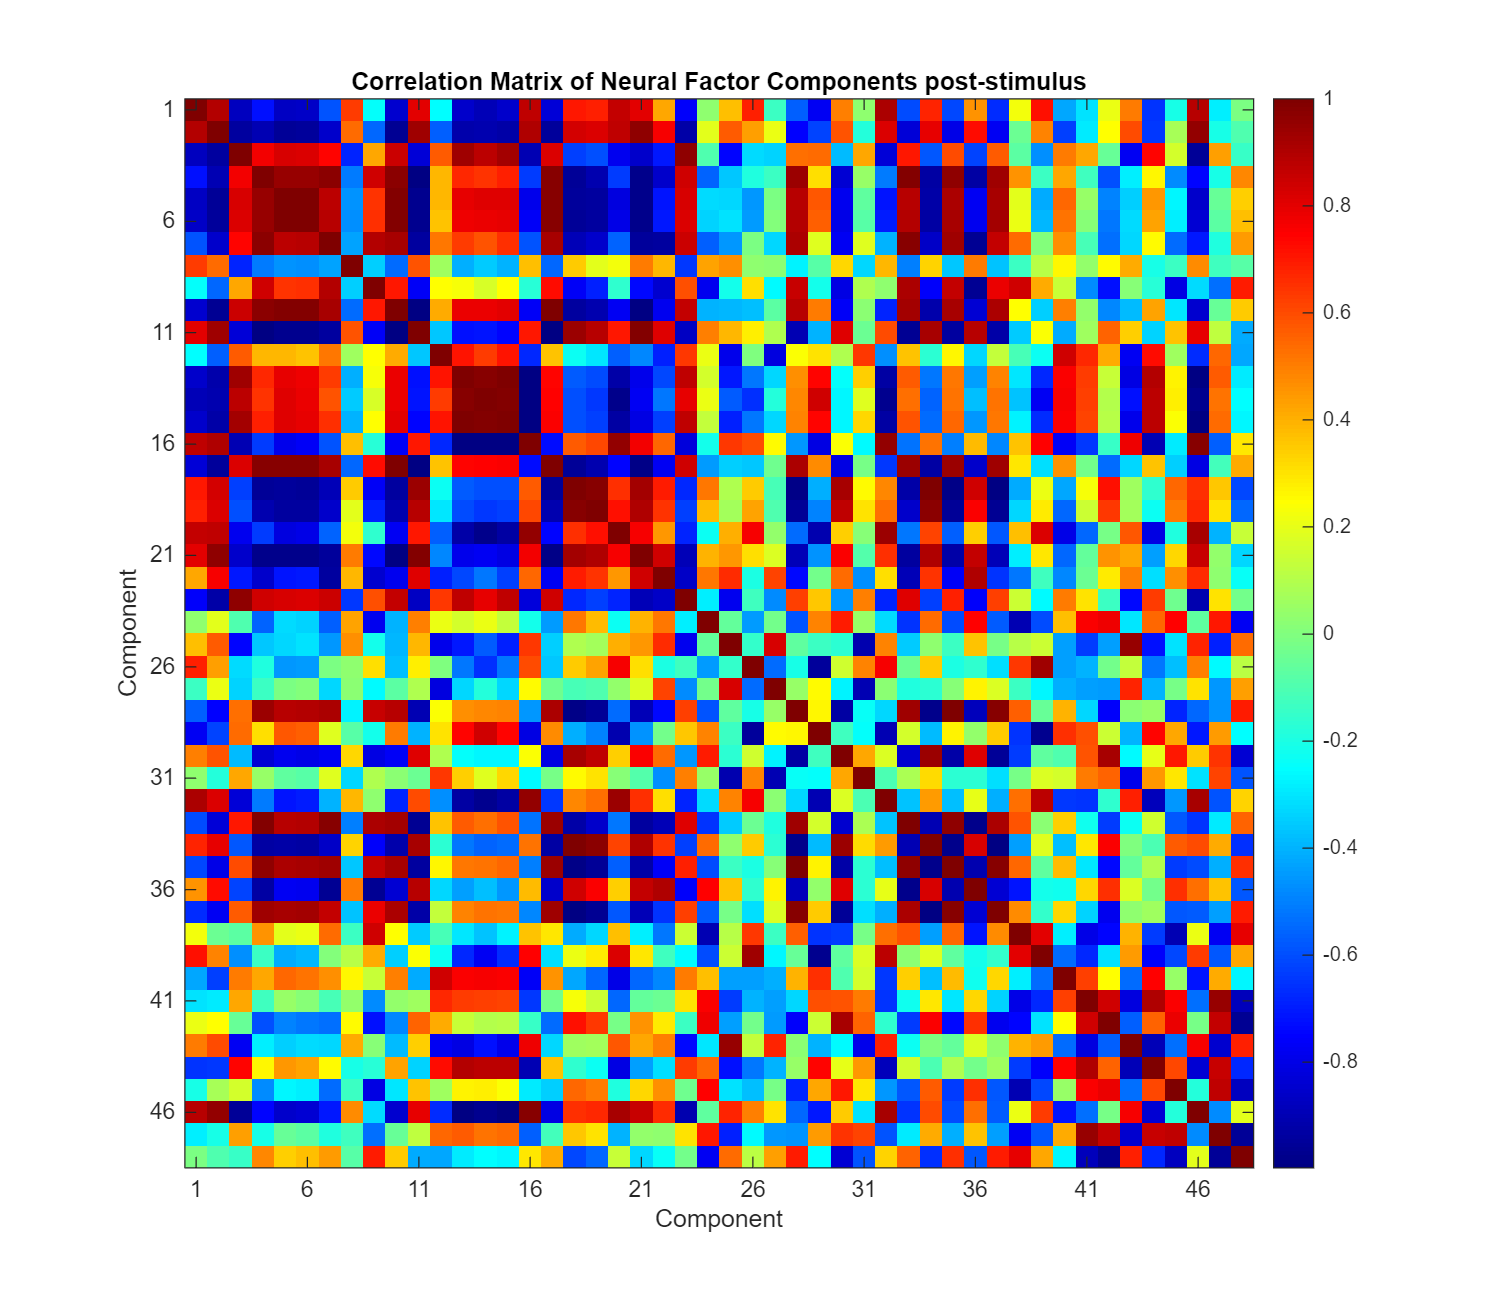


% Create correlation matrix for neural factor U_post{1}
% Each column in U_post{1} represents a component, so we compute correlations between components
correlation_matrix_post = corrcoef(U_post{1});

% Plot the correlation matrix
figure('Position', [100, 100, 800, 700]);
imagesc(correlation_matrix_post);
colormap('jet');
colorbar;
axis square;
title('Correlation Matrix of Neural Factor Components post-stimulus');
xlabel('Component');
ylabel('Component');

% Add component numbers to the tick labels
num_components_post = size(correlation_matrix_post, 1);
xticks(1:num_components_post);
yticks(1:num_components_post);

% If there are many components, you might want to show tick labels at intervals
if num_components_post > 20
    xticks(1:5:num_components_post);
    yticks(1:5:num_components_post);
end

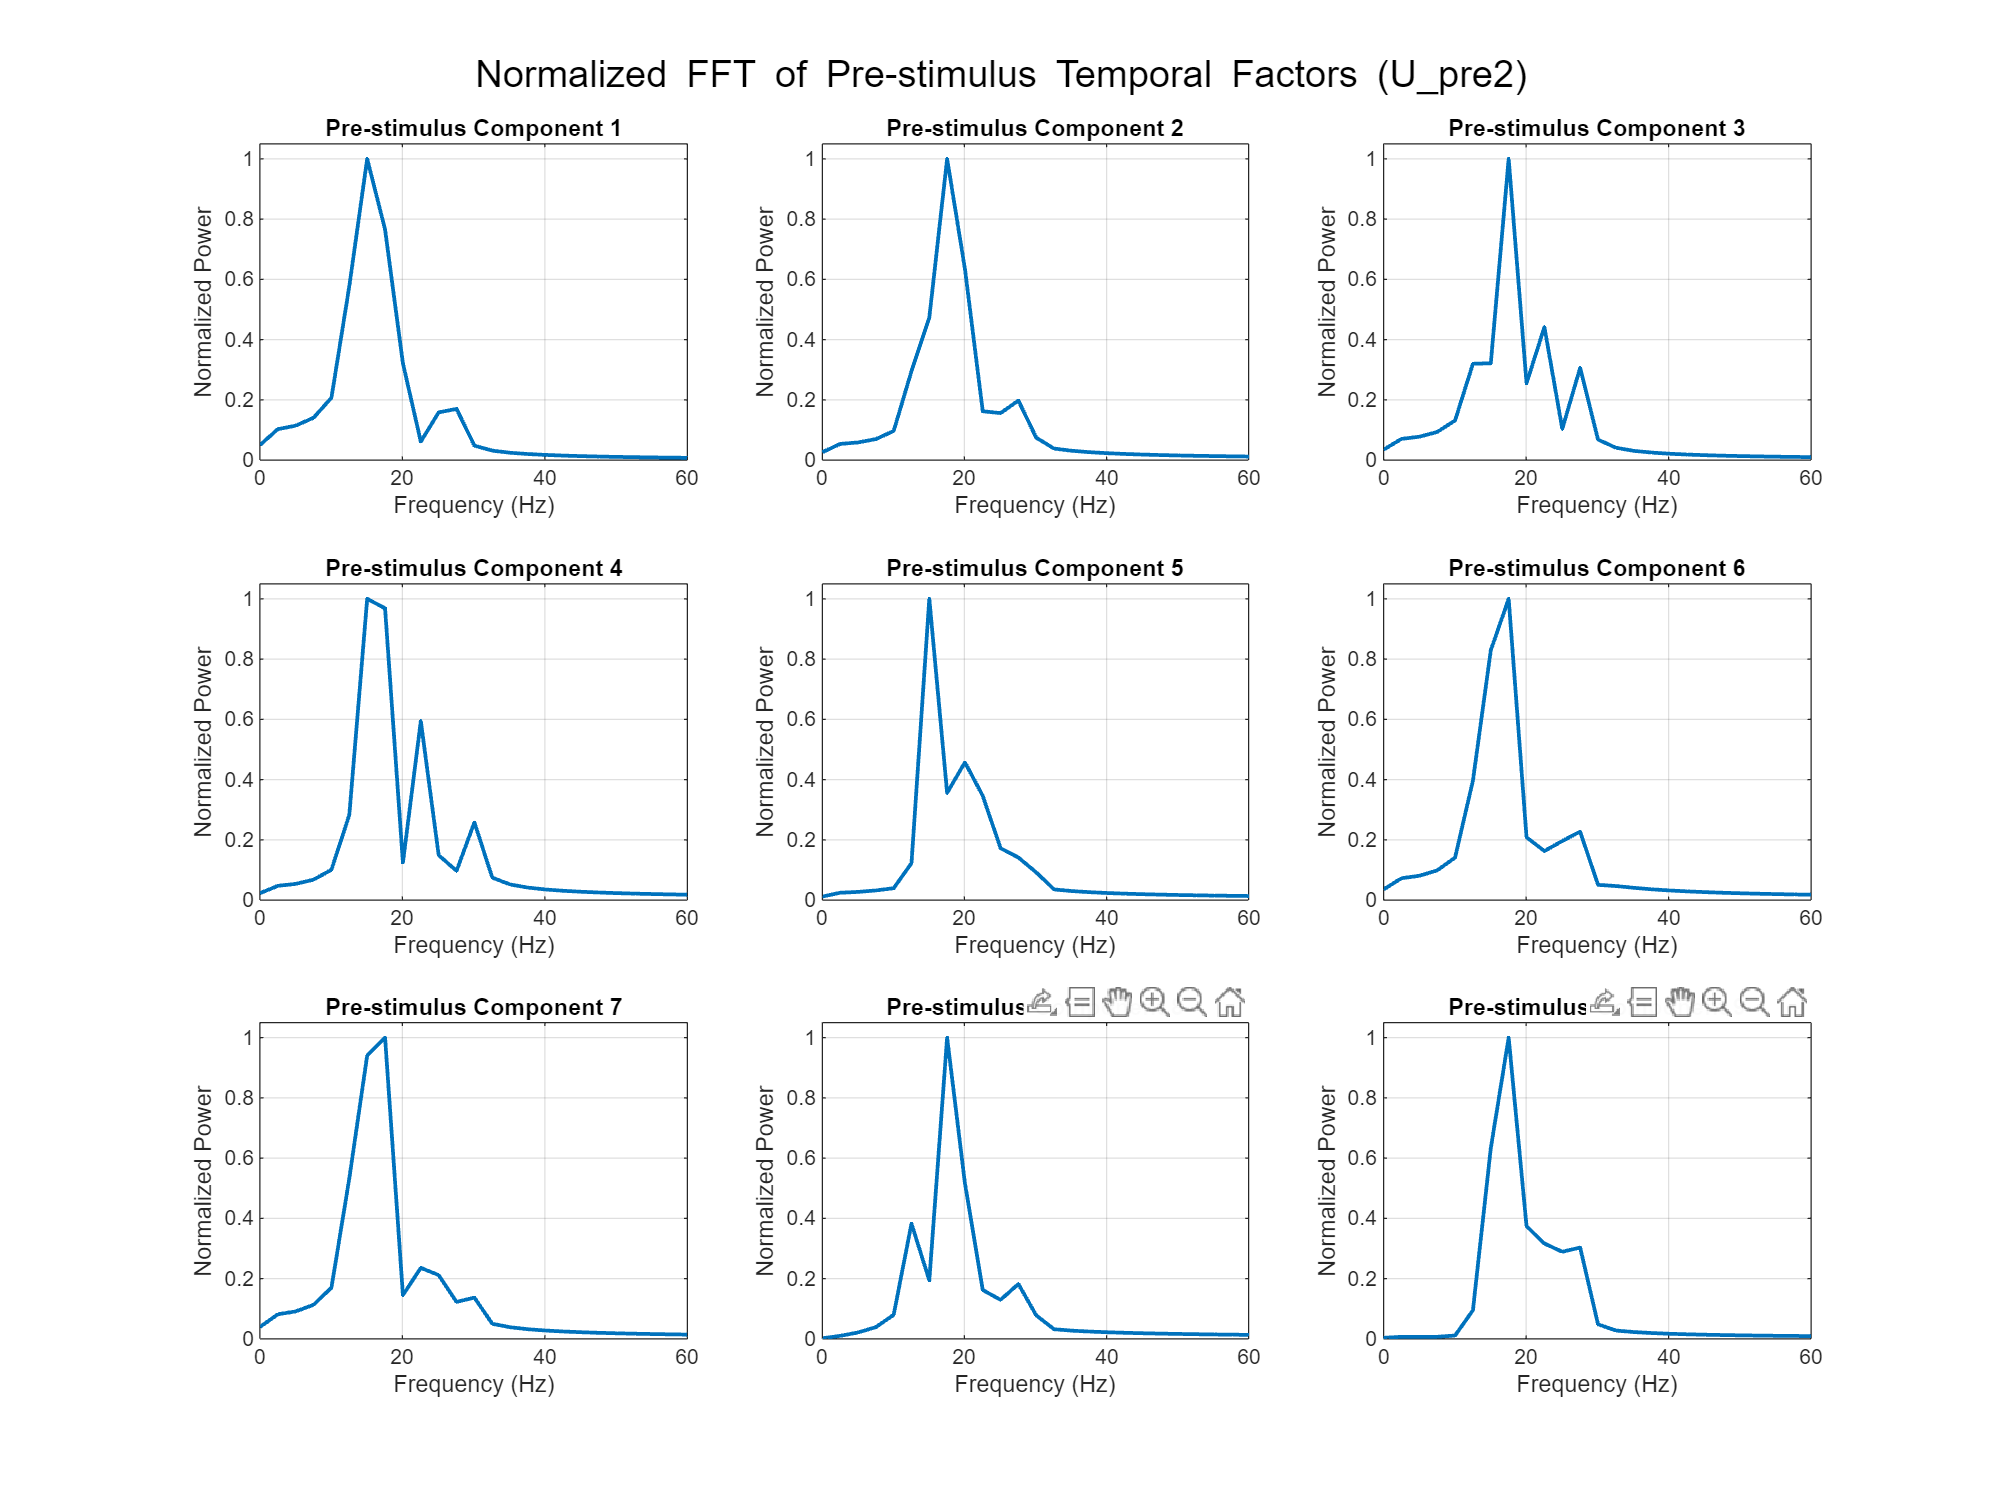

% Temporal factor analysis: FFT
% FFT analysis on temporal factors with normalization

% Define parameters for FFT
sampling_rate = fs; % Use your original sampling rate from EEG data
time_pre = time_vector(pre_idx);
time_post = time_vector(post_idx);
dt_pre = mean(diff(time_pre)); % Time step for pre-stimulus
dt_post = mean(diff(time_post)); % Time step for post-stimulus

% Calculate frequency axis
N_pre = length(time_pre);
freq_pre = (0:N_pre-1)/(N_pre*dt_pre); % Frequency axis in Hz
freq_pre = freq_pre(1:floor(N_pre/2)+1); % Keep only positive frequencies

N_post = length(time_post);
freq_post = (0:N_post-1)/(N_post*dt_post); % Frequency axis in Hz
freq_post = freq_post(1:floor(N_post/2)+1); % Keep only positive frequencies

% Preallocate arrays to store power spectra for normalization
pre_power_spectra = zeros(length(freq_pre), 9);
post_power_spectra = zeros(length(freq_post), 9);

% Compute FFT for all pre-stimulus components
for comp = 1:9
    signal = U_pre{2}(:, comp);
    Y = fft(signal);
    P2 = abs(Y/N_pre);
    P1 = P2(1:floor(N_pre/2)+1);
    P1(2:end-1) = 2*P1(2:end-1);
    pre_power_spectra(:, comp) = P1;
end

% Compute FFT for all post-stimulus components
for comp = 1:9
    signal = U_post{2}(:, comp);
    Y = fft(signal);
    P2 = abs(Y/N_post);
    P1 = P2(1:floor(N_post/2)+1);
    P1(2:end-1) = 2*P1(2:end-1);
    post_power_spectra(:, comp) = P1;
end

% Normalize each power spectrum by its maximum value
for comp = 1:9
    pre_power_spectra(:, comp) = pre_power_spectra(:, comp) / max(pre_power_spectra(:, comp));
    post_power_spectra(:, comp) = post_power_spectra(:, comp) / max(post_power_spectra(:, comp));
end

% Create figures for pre-stimulus components with normalized power
figure('Position', [100, 100, 1200, 900]);
for comp = 1:9
    subplot(3, 3, comp);
    plot(freq_pre, pre_power_spectra(:, comp), 'LineWidth', 1.5);
    grid on;
    title(['Pre-stimulus Component ', num2str(comp)]);
    xlabel('Frequency (Hz)');
    ylabel('Normalized Power');
    xlim([0, min(60, max(freq_pre))]);
    ylim([0, 1.05]); % Set y-axis limit to be consistent
end
sgtitle('Normalized FFT of Pre-stimulus Temporal Factors (U\_pre{2})');

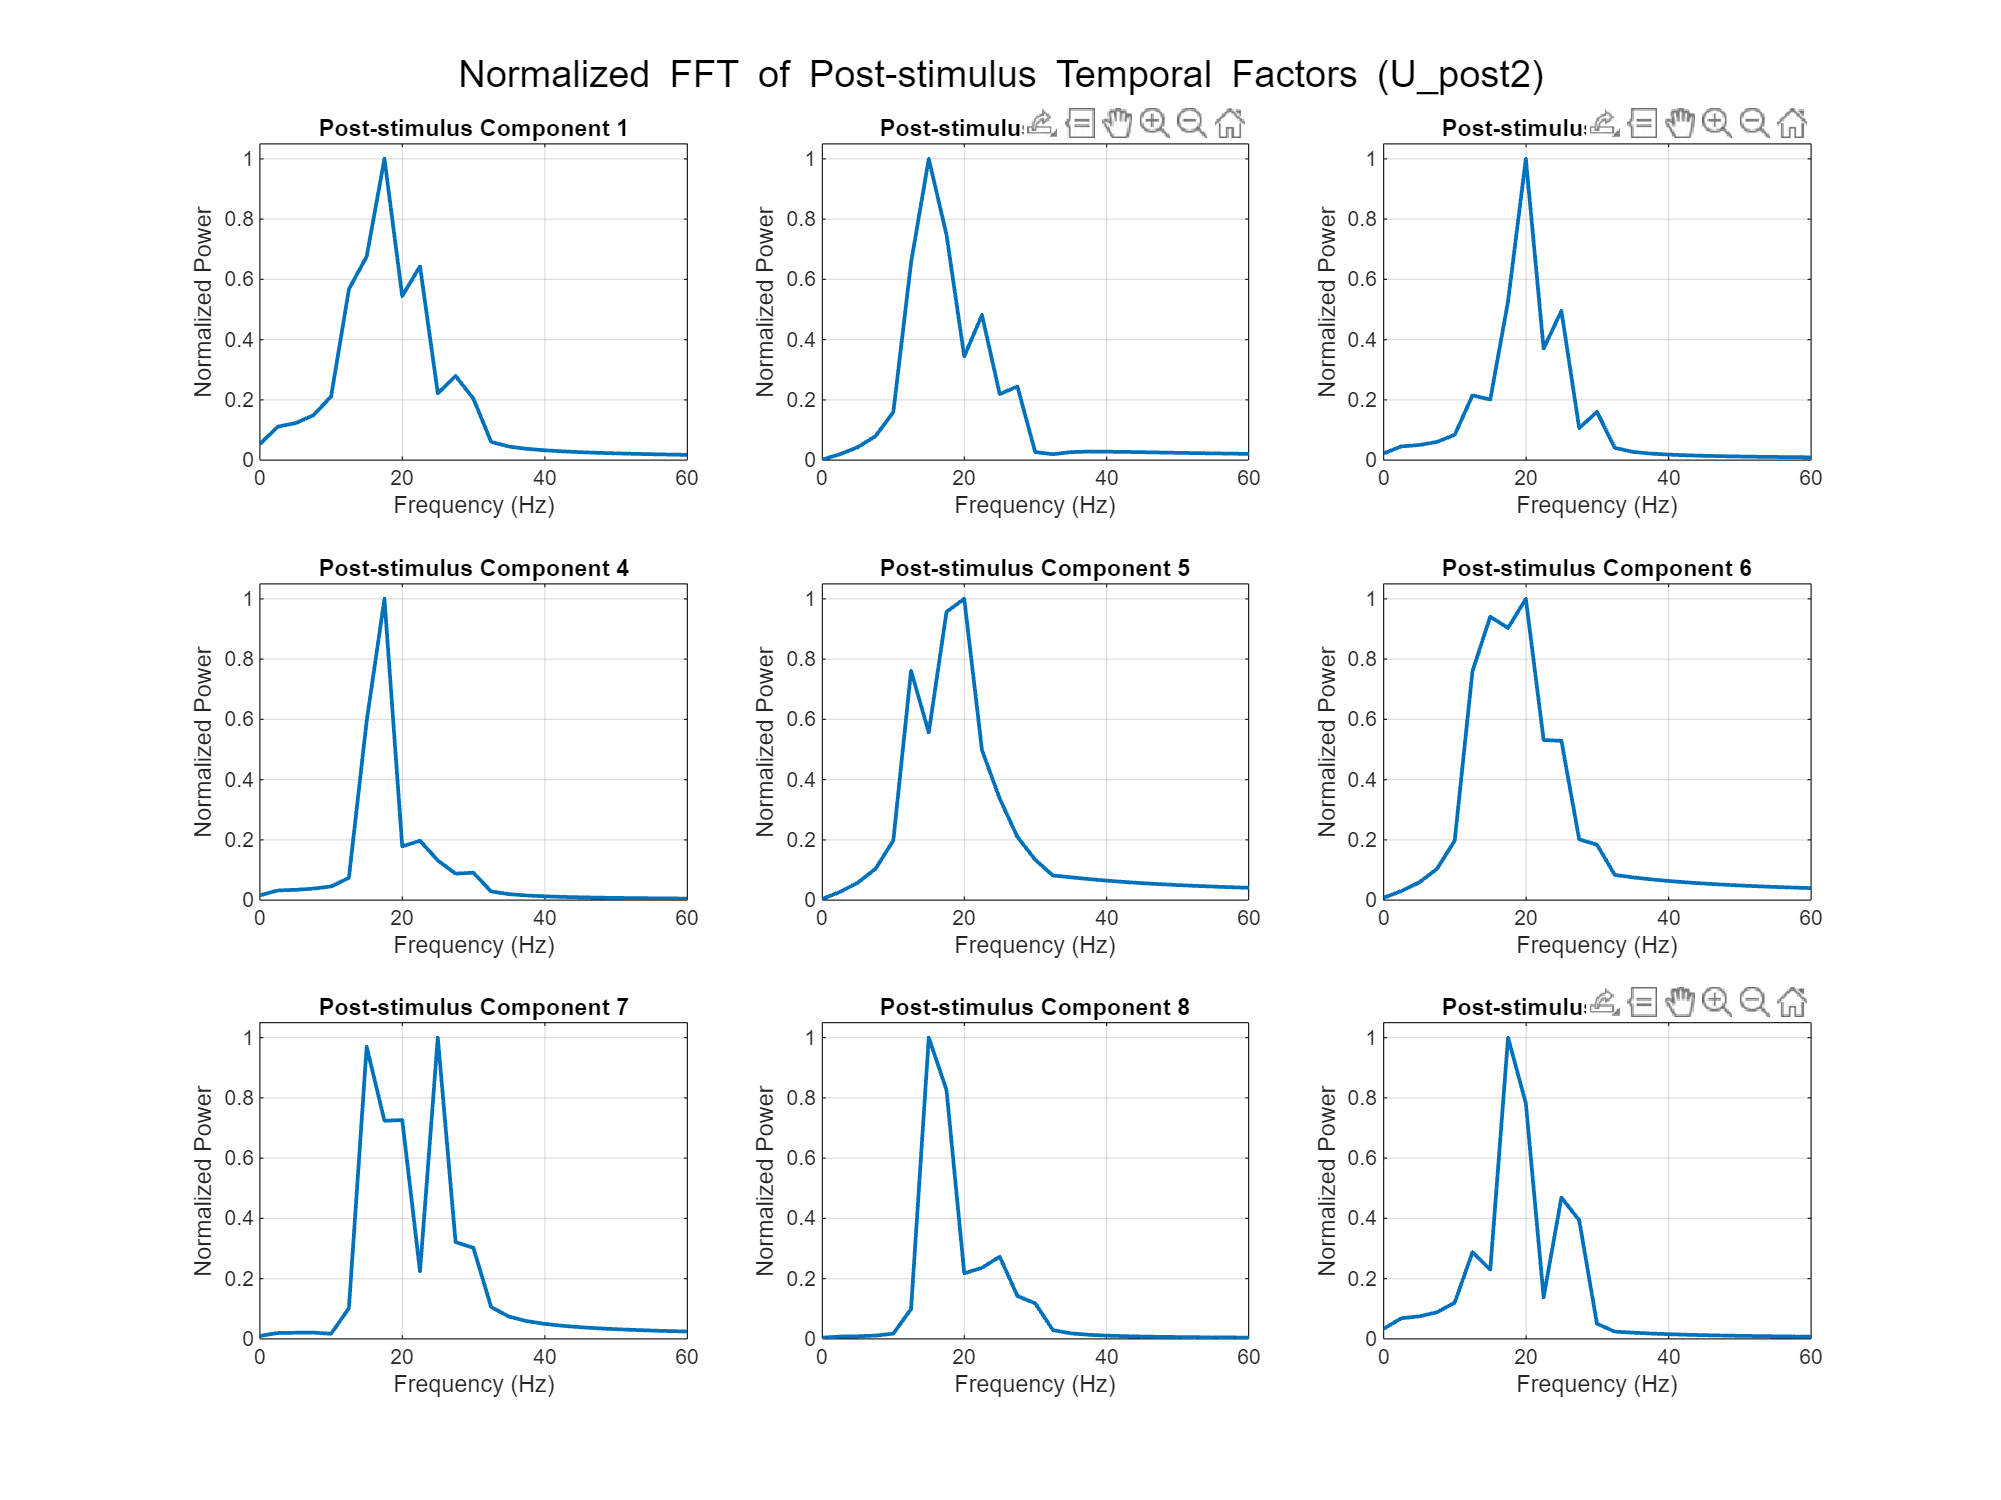


% Create figures for post-stimulus components with normalized power
figure('Position', [100, 100, 1200, 900]);
for comp = 1:9
    subplot(3, 3, comp);
    plot(freq_post, post_power_spectra(:, comp), 'LineWidth', 1.5);
    grid on;
    title(['Post-stimulus Component ', num2str(comp)]);
    xlabel('Frequency (Hz)');
    ylabel('Normalized Power');
    xlim([0, min(60, max(freq_post))]);
    ylim([0, 1.05]); % Set y-axis limit to be consistent
end
sgtitle('Normalized FFT of Post-stimulus Temporal Factors (U\_post{2})');

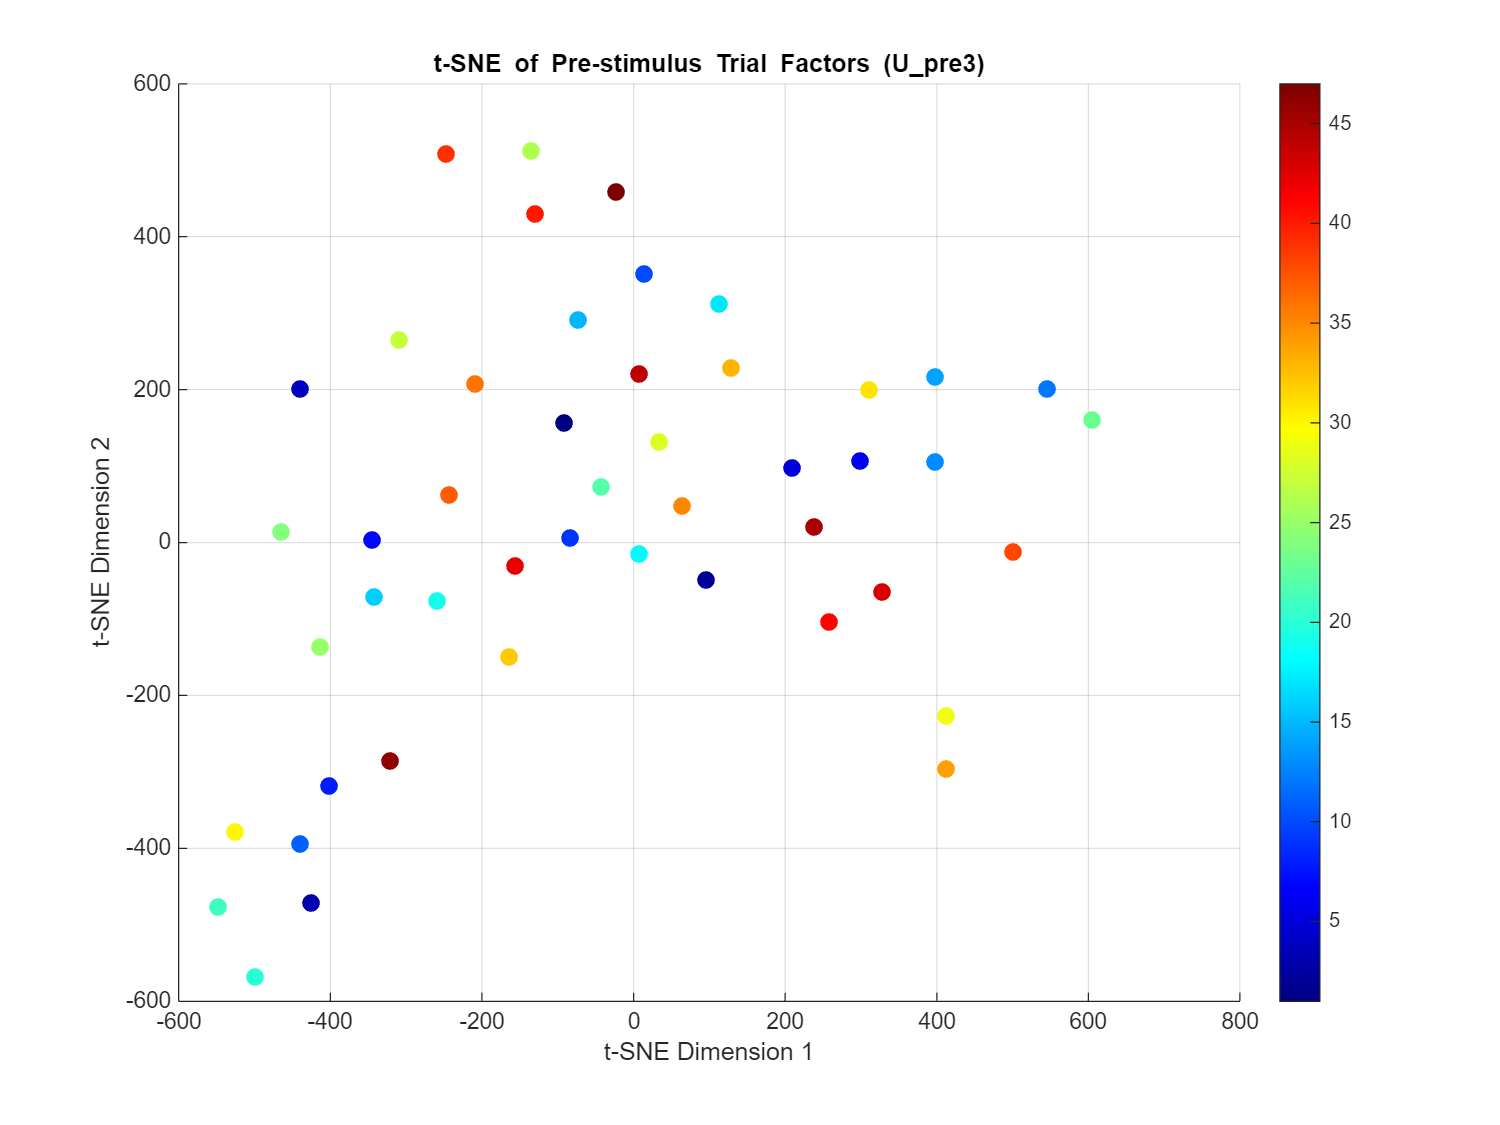

% Trial Factor analysis: t-SNE clustering

% t-SNE clustering on trial factors U_pre{3} and U_post{3}

% Check if Statistics and Machine Learning Toolbox is installed (required for tsne)
if ~license('test', 'Statistics_Toolbox')
    warning('Statistics and Machine Learning Toolbox might not be installed. You may need to install it to run t-SNE.');
end

% Parameters for t-SNE
perplexity = 12; % Default perplexity - adjust based on your number of trials, n/3, 60/3 =20
num_dims = 2;    % 2D visualization

% t-SNE for pre-stimulus trial factors
% Transpose the matrix so each row represents a trial
trial_factors_pre = U_pre{3}';
Y_pre = tsne(trial_factors_pre, 'Perplexity', min(perplexity, size(trial_factors_pre, 1)-1), 'NumDimensions', num_dims);

% t-SNE for post-stimulus trial factors
trial_factors_post = U_post{3}';
Y_post = tsne(trial_factors_post, 'Perplexity', min(perplexity, size(trial_factors_post, 1)-1), 'NumDimensions', num_dims);

% Plot pre-stimulus t-SNE results
figure('Position', [100, 100, 800, 600]);
scatter(Y_pre(:,1), Y_pre(:,2), 50, 1:size(Y_pre,1), 'filled');
colormap(jet);
colorbar;
title('t-SNE of Pre-stimulus Trial Factors (U\_pre{3})');
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
grid on;

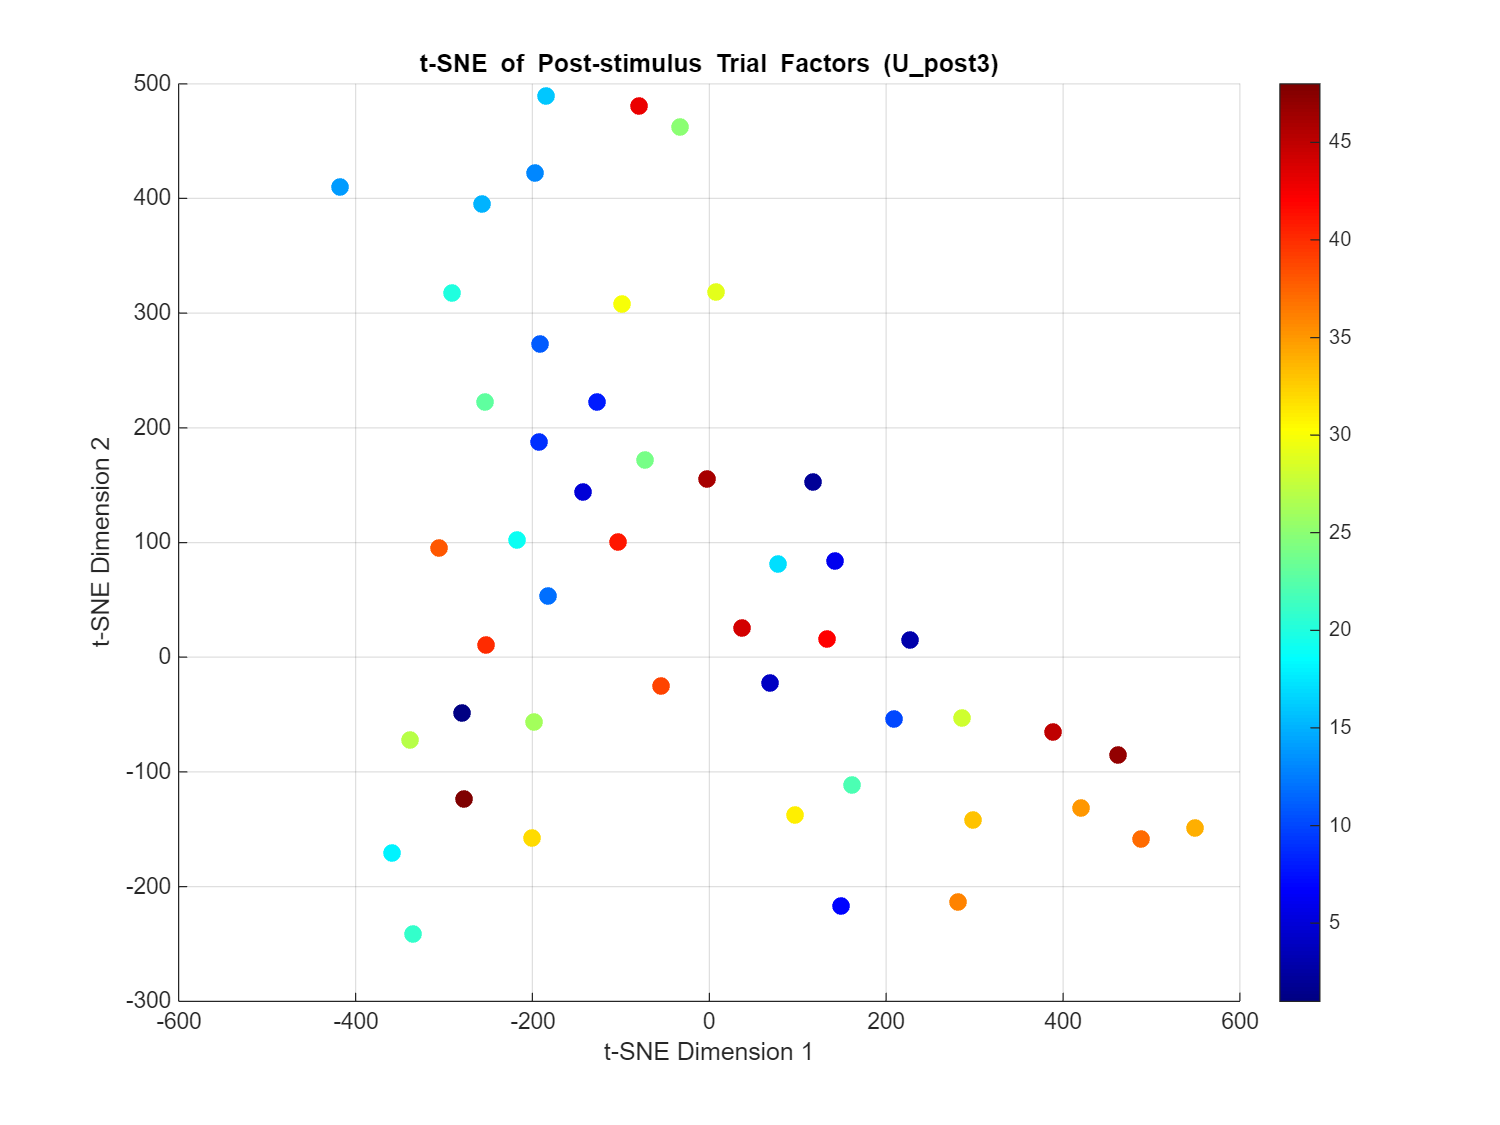


% Plot post-stimulus t-SNE results
figure('Position', [100, 100, 800, 600]);
scatter(Y_post(:,1), Y_post(:,2), 50, 1:size(Y_post,1), 'filled');
colormap(jet);
colorbar;
title('t-SNE of Post-stimulus Trial Factors (U\_post{3})');
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
grid on;

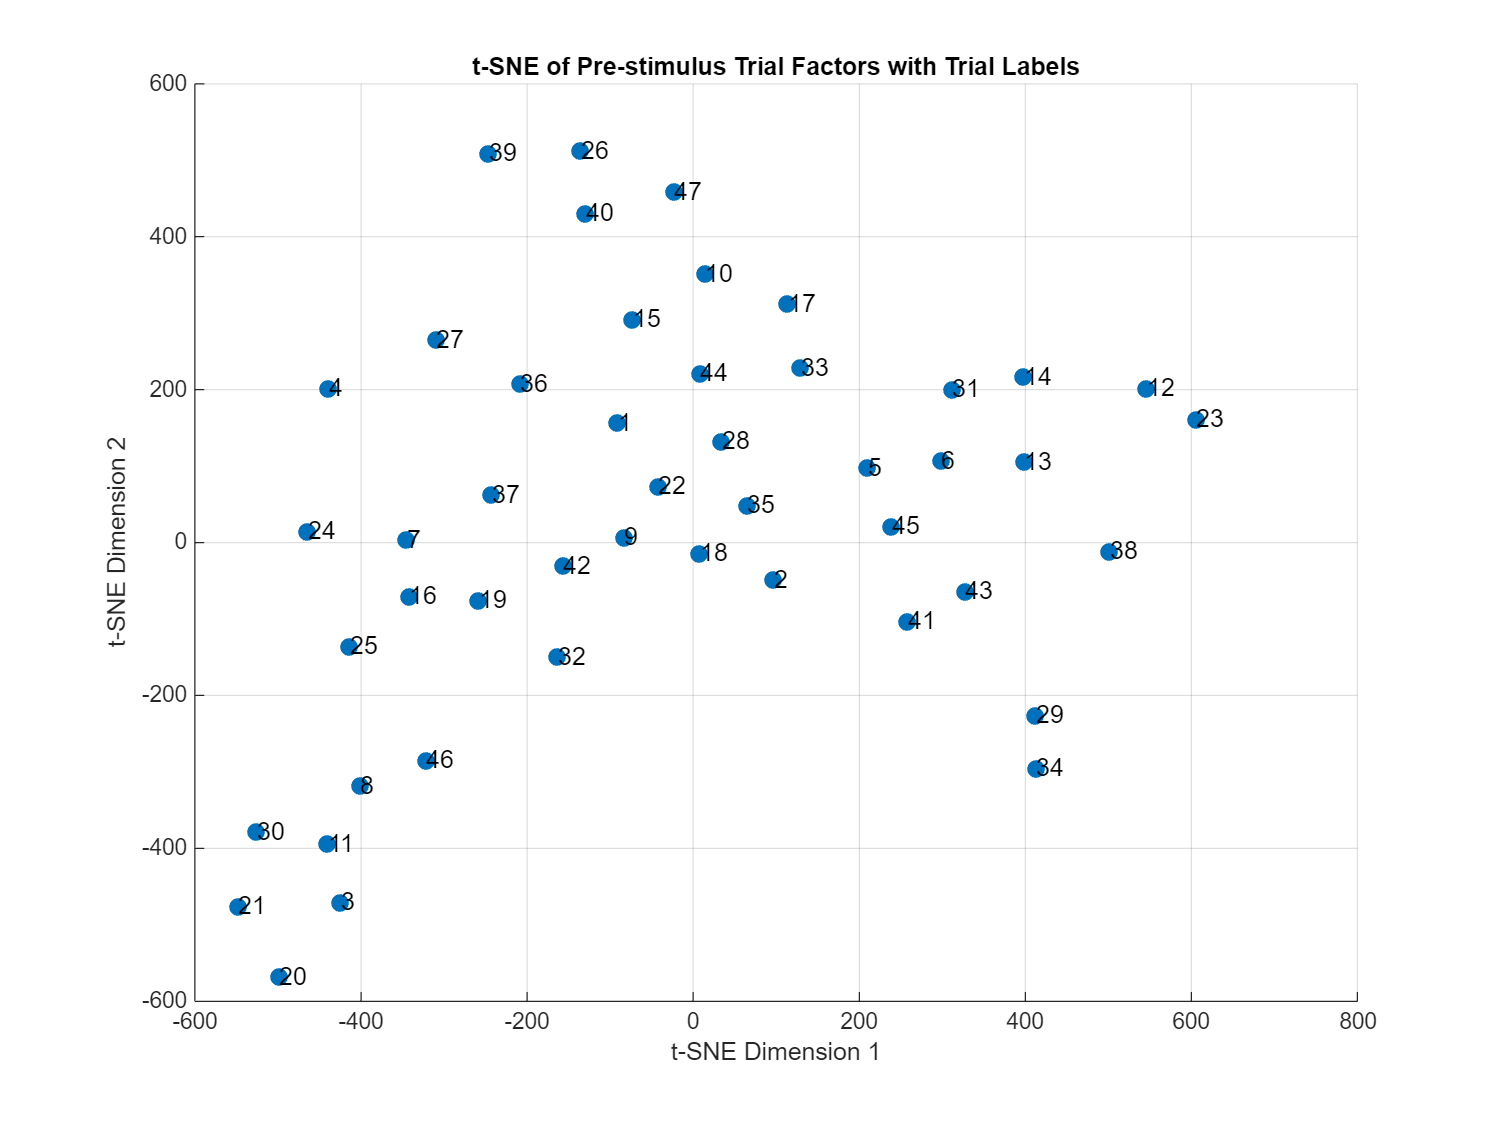


% Alternative visualization: Plot with trial numbers as labels
figure('Position', [100, 100, 800, 600]);
scatter(Y_pre(:,1), Y_pre(:,2), 50, 'filled');
title('t-SNE of Pre-stimulus Trial Factors with Trial Labels');
xlabel('t-SNE Dimension 1'); 
ylabel('t-SNE Dimension 2');
grid on;
% Add trial numbers as text labels (may be crowded with many trials)
for i = 1:size(Y_pre, 1)
    text(Y_pre(i,1), Y_pre(i,2), num2str(i), 'FontSize', 10);
end

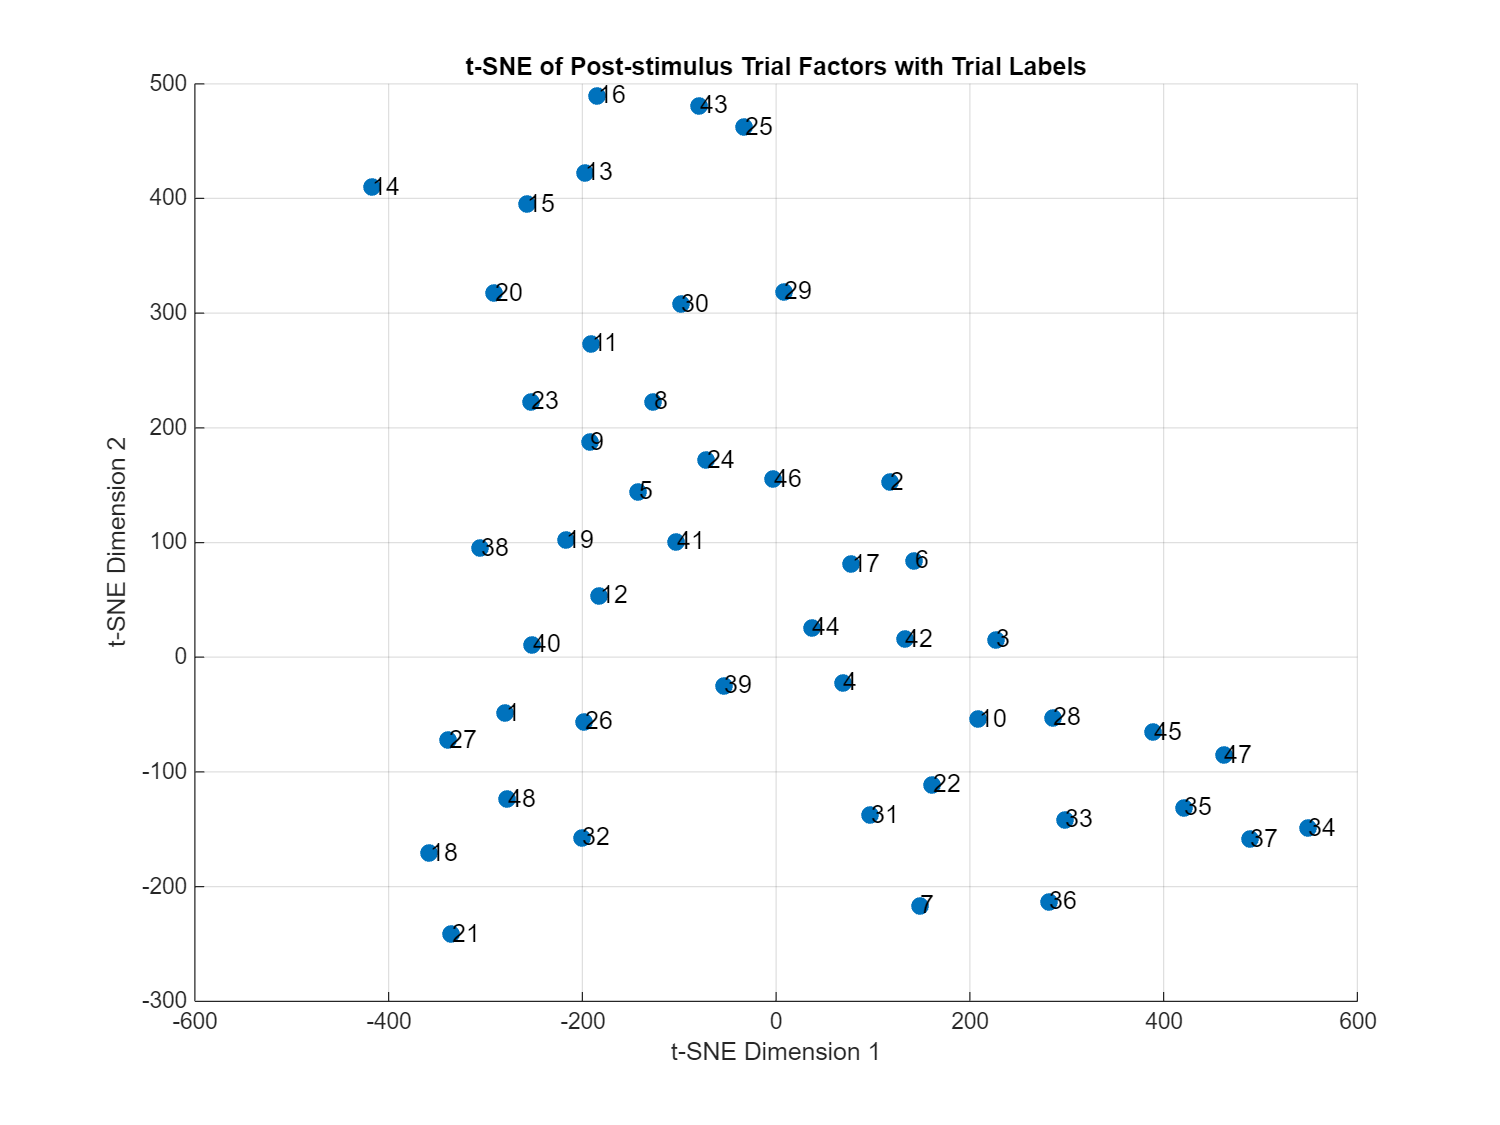


figure('Position', [100, 100, 800, 600]);
scatter(Y_post(:,1), Y_post(:,2), 50, 'filled');
title('t-SNE of Post-stimulus Trial Factors with Trial Labels');
xlabel('t-SNE Dimension 1'); 
ylabel('t-SNE Dimension 2');
grid on;
% Add trial numbers as text labels (may be crowded with many trials)
for i = 1:size(Y_post, 1)
    text(Y_post(i,1), Y_post(i,2), num2str(i), 'FontSize', 10);
end

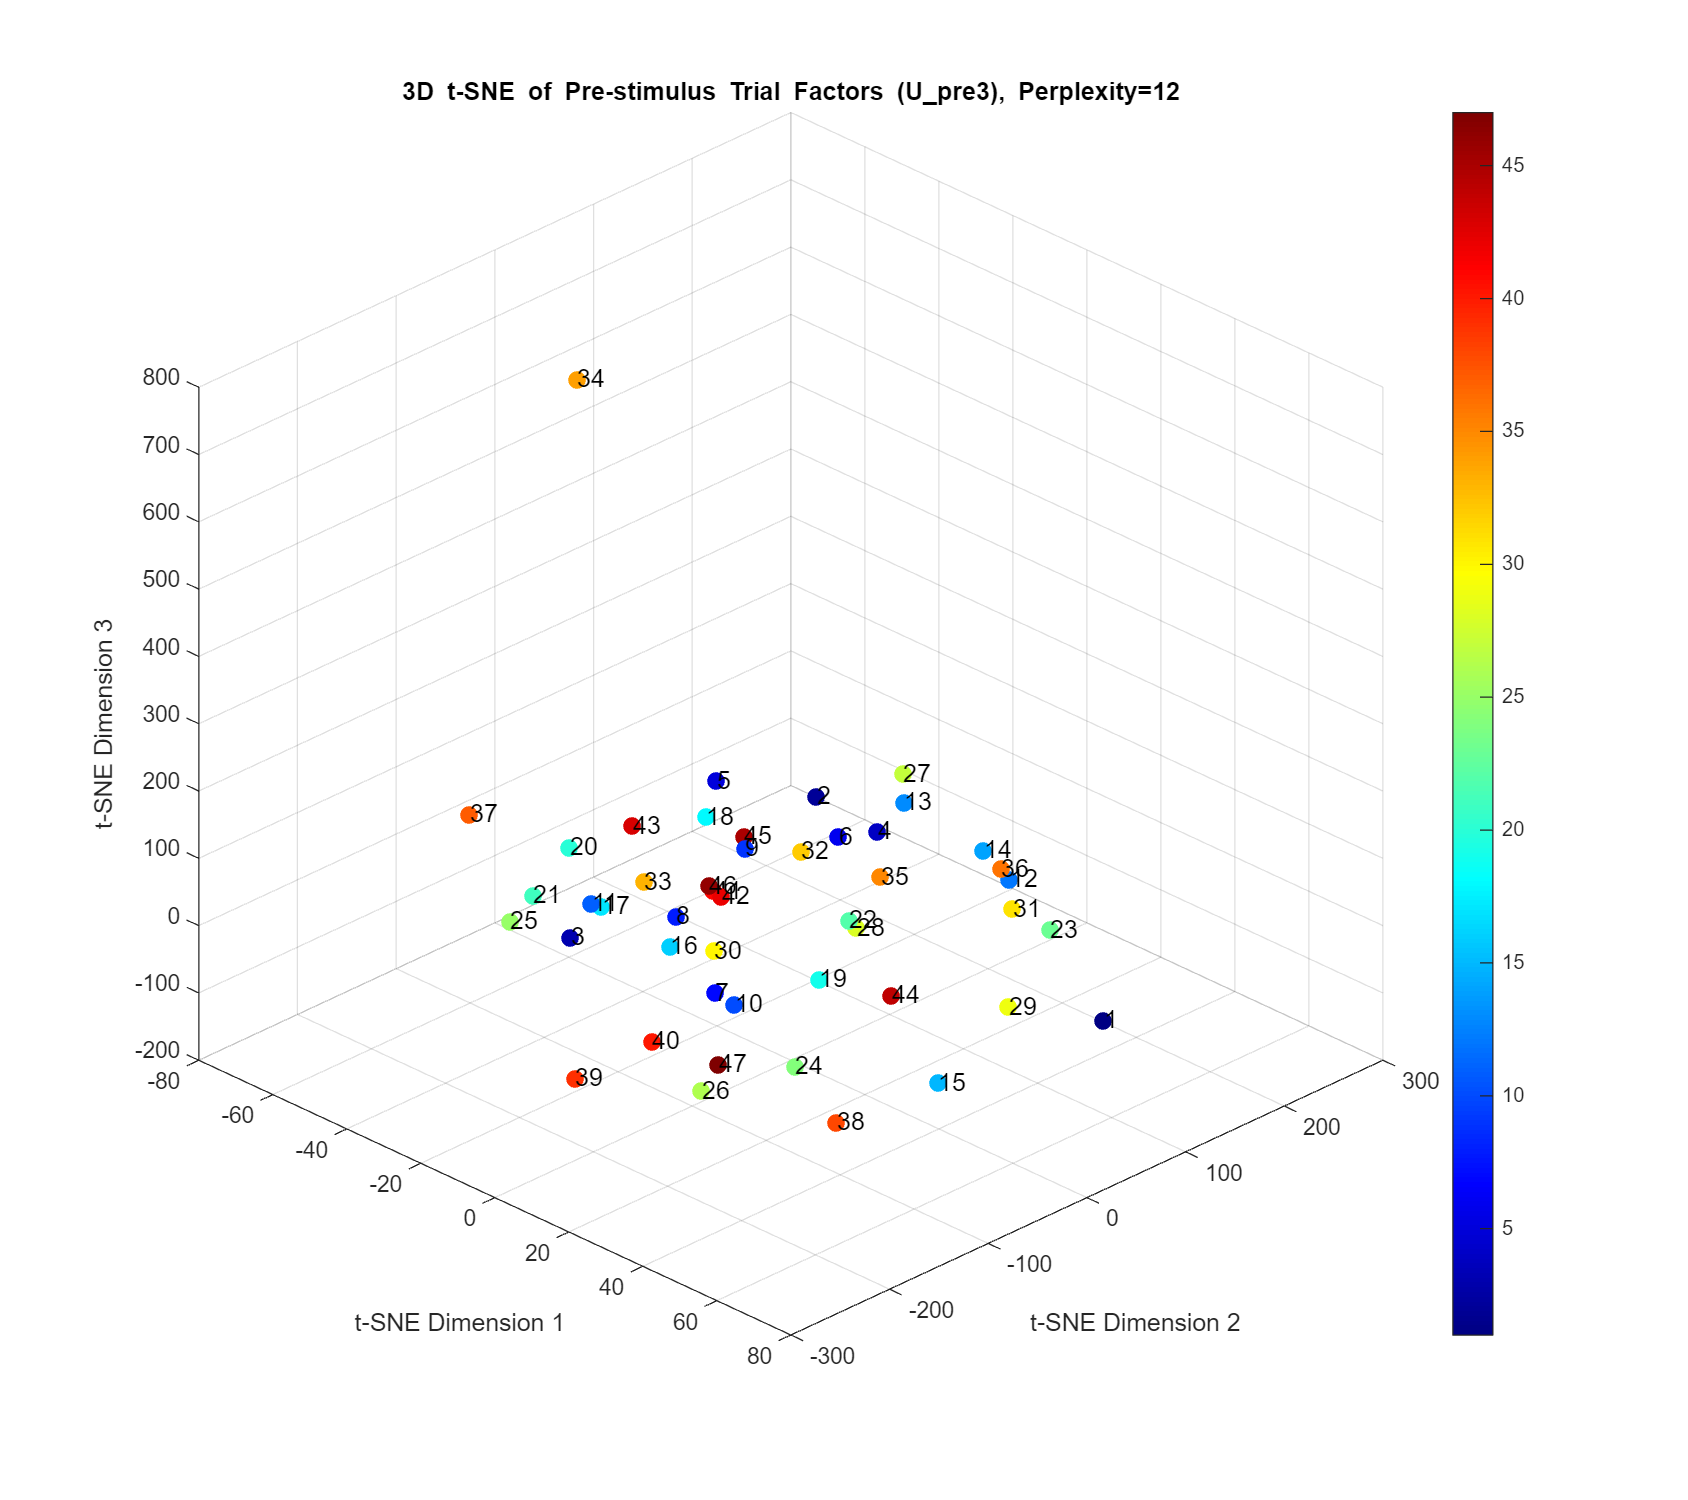


% t-SNE clustering on trial factors U_pre{3} and U_post{3} with 3D visualization

% Check if Statistics and Machine Learning Toolbox is installed (required for tsne)
if ~license('test', 'Statistics_Toolbox')
    warning('Statistics and Machine Learning Toolbox might not be installed. You may need to install it to run t-SNE.');
end

% Parameters for t-SNE
% perplexity = 10;  % Set perplexity to 60 as requested
num_dims = 3;     % 3D visualization

% t-SNE for pre-stimulus trial factors
% Transpose the matrix so each row represents a trial
trial_factors_pre = U_pre{3}';
Y_pre = tsne(trial_factors_pre, 'Perplexity', min(perplexity, size(trial_factors_pre, 1)-1), 'NumDimensions', num_dims);

% t-SNE for post-stimulus trial factors
trial_factors_post = U_post{3}';
Y_post = tsne(trial_factors_post, 'Perplexity', min(perplexity, size(trial_factors_post, 1)-1), 'NumDimensions', num_dims);

% 3D Plot for pre-stimulus t-SNE results with trial labels
figure('Position', [100, 100, 900, 800]);
scatter3(Y_pre(:,1), Y_pre(:,2), Y_pre(:,3), 50, 1:size(Y_pre,1), 'filled');
colormap(jet);
colorbar;
title('3D t-SNE of Pre-stimulus Trial Factors (U\_pre{3}), Perplexity=12');
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
zlabel('t-SNE Dimension 3');
grid on;

% Add trial numbers as text labels
for i = 1:size(Y_pre, 1)
    text(Y_pre(i,1), Y_pre(i,2), Y_pre(i,3), num2str(i), 'FontSize', 10);
end

% Improve the view angle for better visualization
view(45, 30);

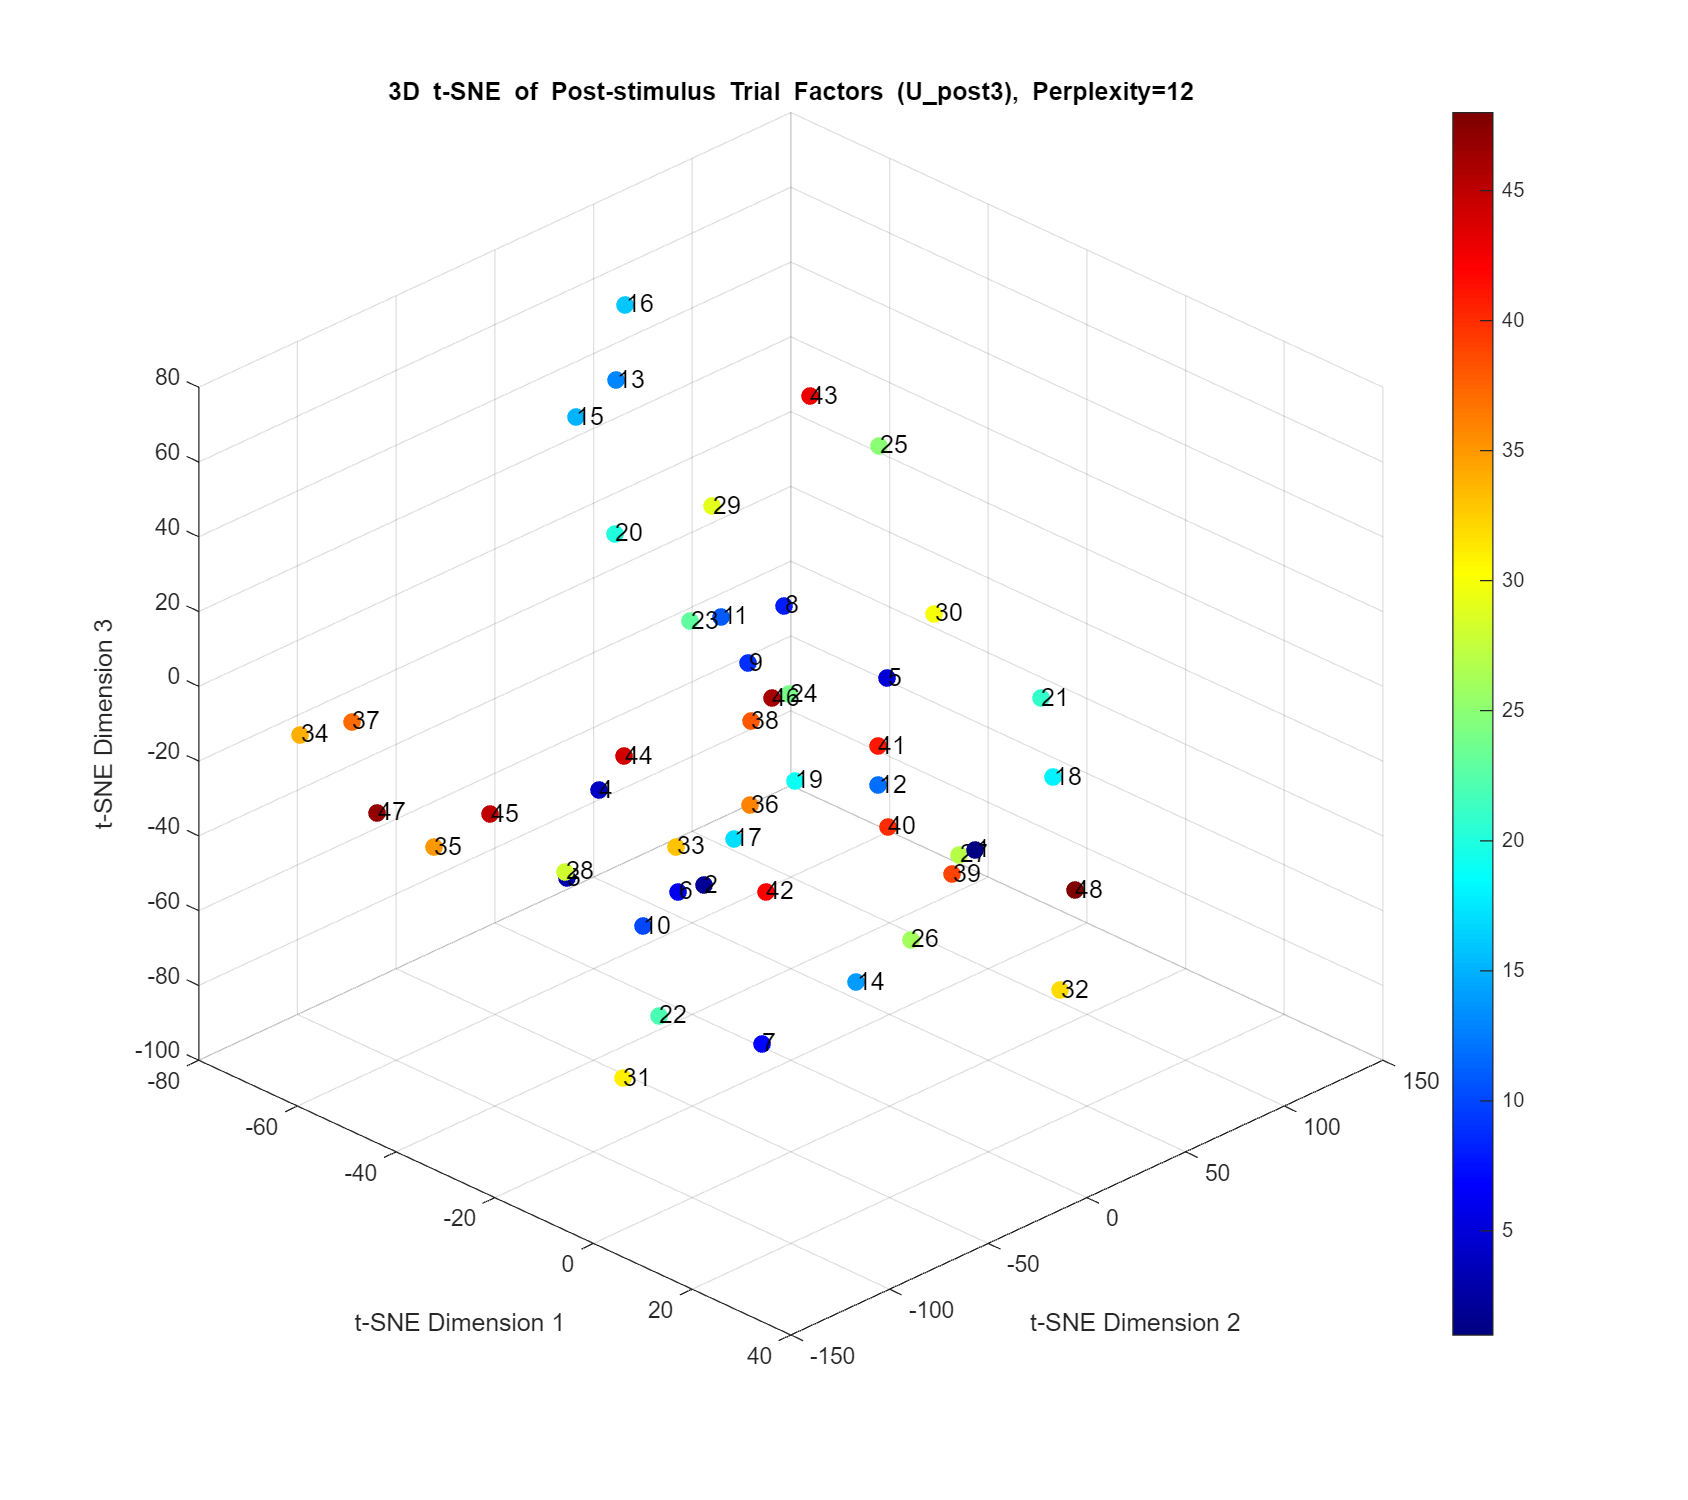


% 3D Plot for post-stimulus t-SNE results with trial labels
figure('Position', [100, 100, 900, 800]);
scatter3(Y_post(:,1), Y_post(:,2), Y_post(:,3), 50, 1:size(Y_post,1), 'filled');
colormap(jet);
colorbar;
title('3D t-SNE of Post-stimulus Trial Factors (U\_post{3}), Perplexity=12');
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
zlabel('t-SNE Dimension 3');
grid on;

% Add trial numbers as text labels
for i = 1:size(Y_post, 1)
    text(Y_post(i,1), Y_post(i,2), Y_post(i,3), num2str(i), 'FontSize', 10);
end

% Improve the view angle for better visualization
view(45, 30);

% Add ability to rotate the 3D plots
rotate3d on;

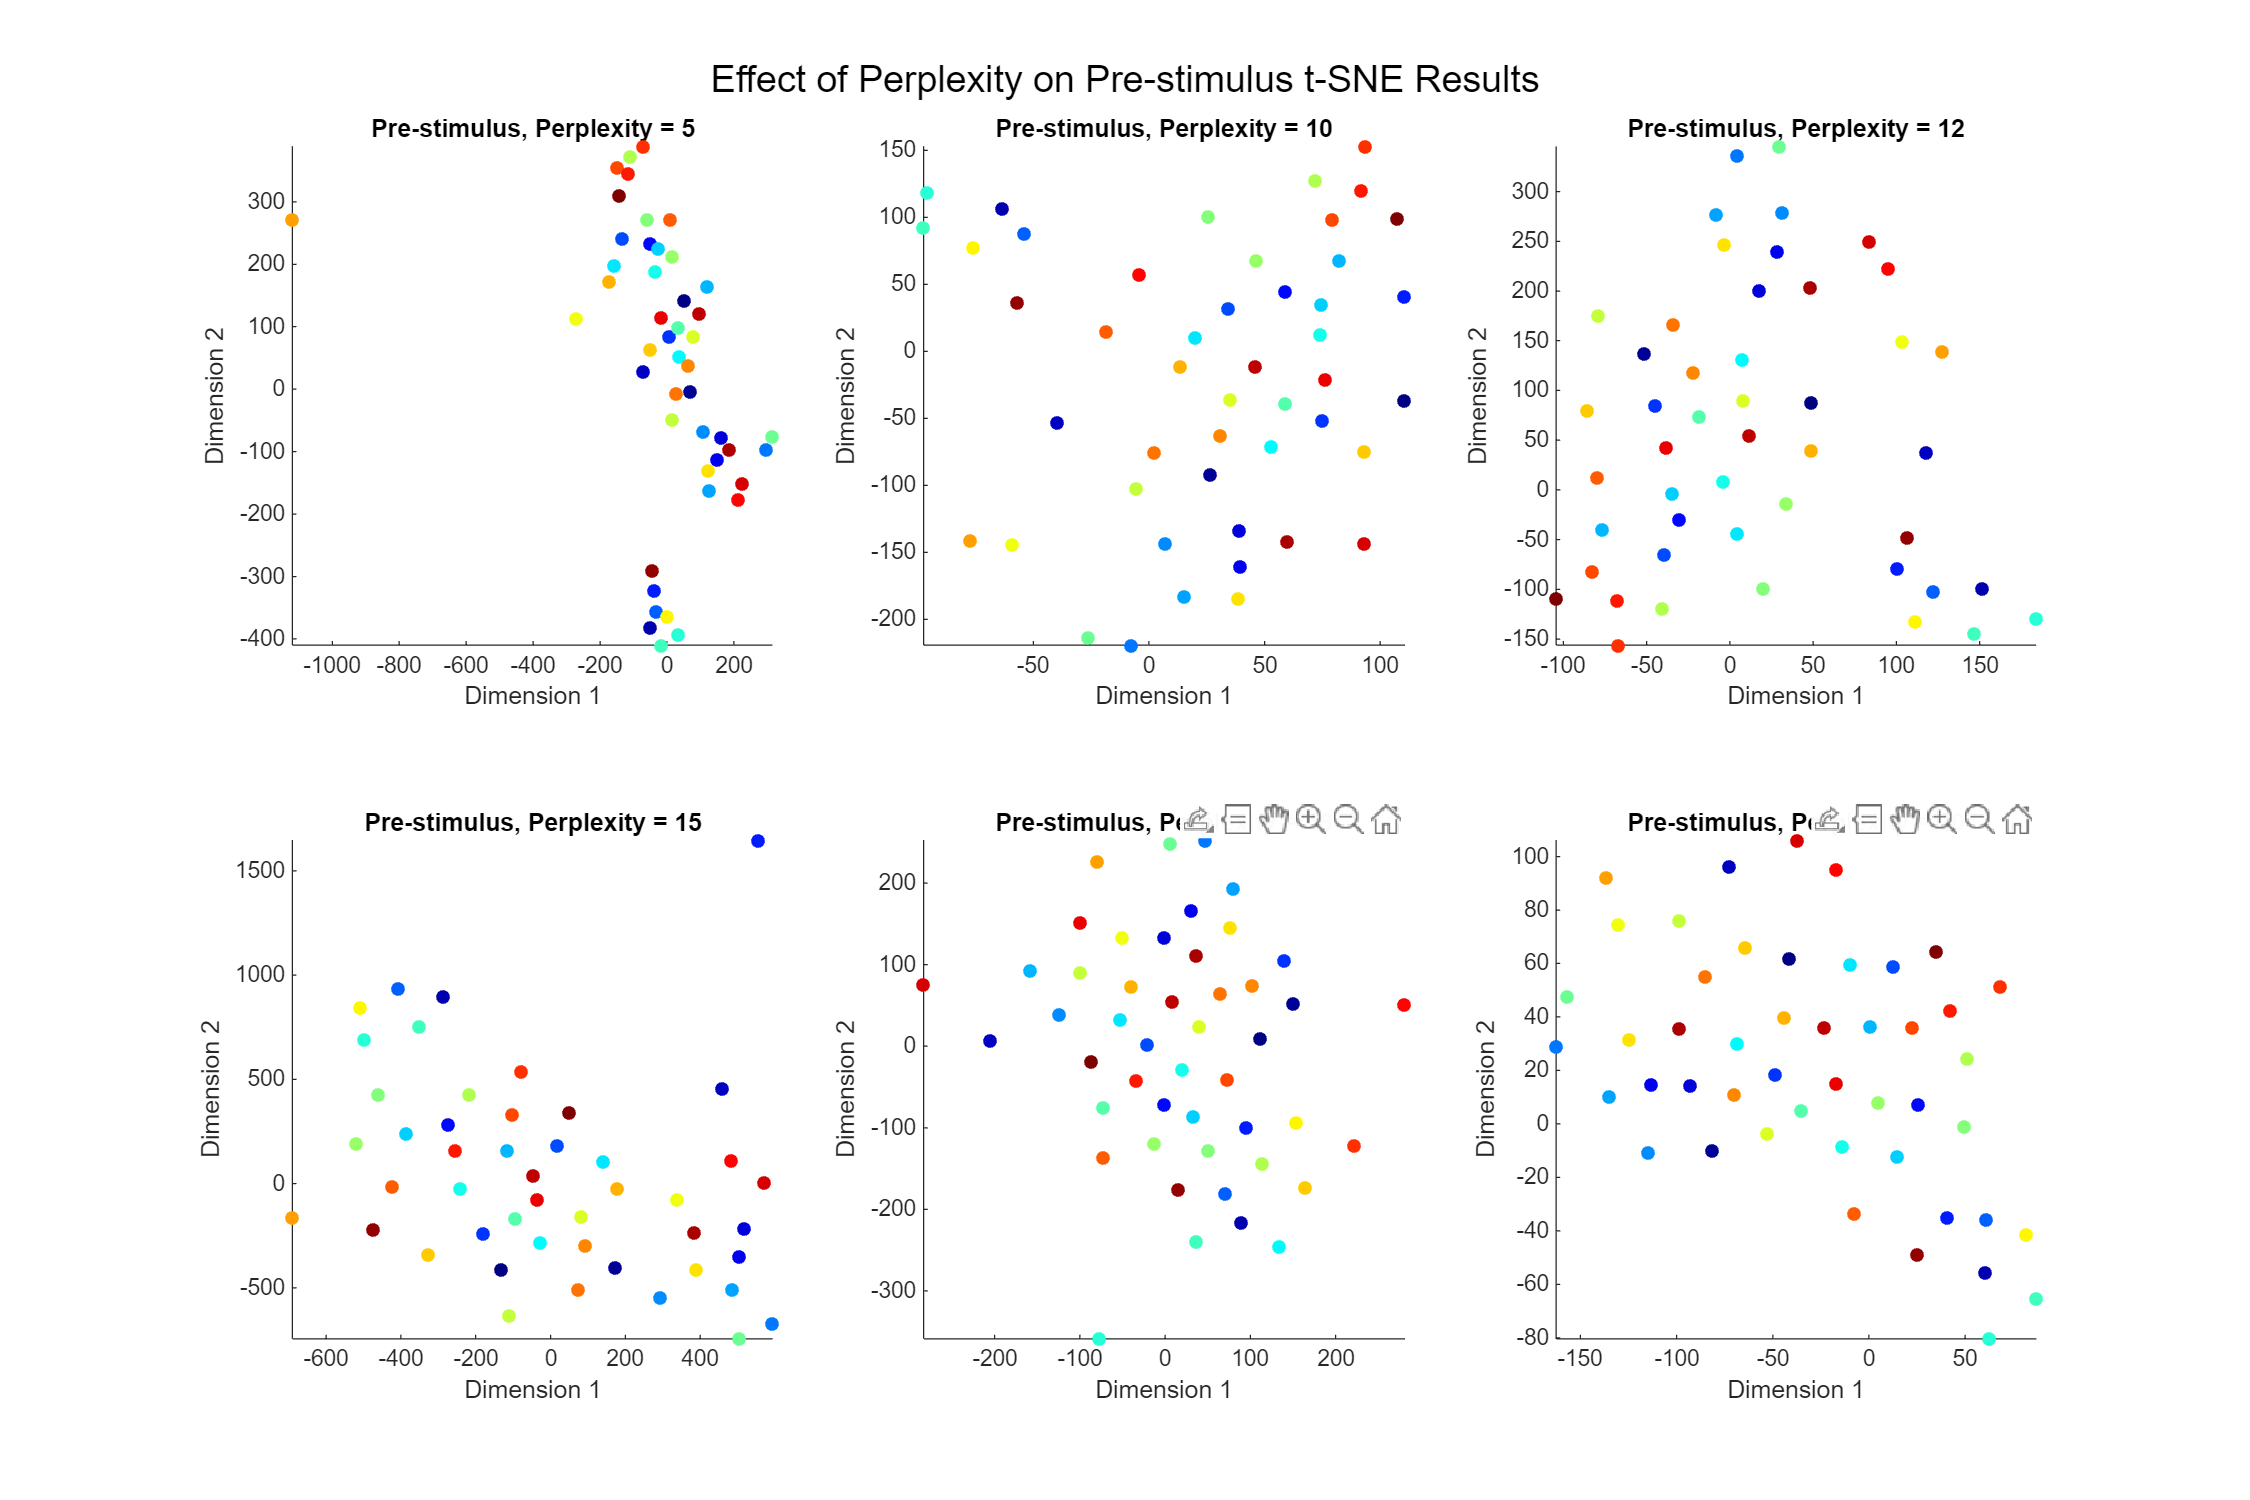

% Systematic approach to selecting perplexity
perplexity_values = [5, 10,12, 15, 18, 20];
num_dims = 2;  % Using 2D for easier comparison

% Preallocate cell arrays to store results
Y_pre_results = cell(length(perplexity_values), 1);
Y_post_results = cell(length(perplexity_values), 1);

% Run t-SNE with different perplexity values
for i = 1:length(perplexity_values)
    perp = perplexity_values(i);
    effective_perp = min(perp, size(trial_factors_pre, 1)-1);
    
    % Pre-stimulus
    Y_pre_results{i} = tsne(trial_factors_pre, 'Perplexity', effective_perp, 'NumDimensions', num_dims);
    
    % Post-stimulus
    Y_post_results{i} = tsne(trial_factors_post, 'Perplexity', effective_perp, 'NumDimensions', num_dims);
end

% Create a grid of plots for pre-stimulus results
figure('Position', [100, 100, 1200, 800]);
for i = 1:length(perplexity_values)
    subplot(2, 3, i);
    scatter(Y_pre_results{i}(:,1), Y_pre_results{i}(:,2), 30, 1:size(Y_pre_results{i},1), 'filled');
    title(['Pre-stimulus, Perplexity = ', num2str(perplexity_values(i))]);
    xlabel('Dimension 1');
    ylabel('Dimension 2');
    colormap(jet);
    axis tight;
end
sgtitle('Effect of Perplexity on Pre-stimulus t-SNE Results');

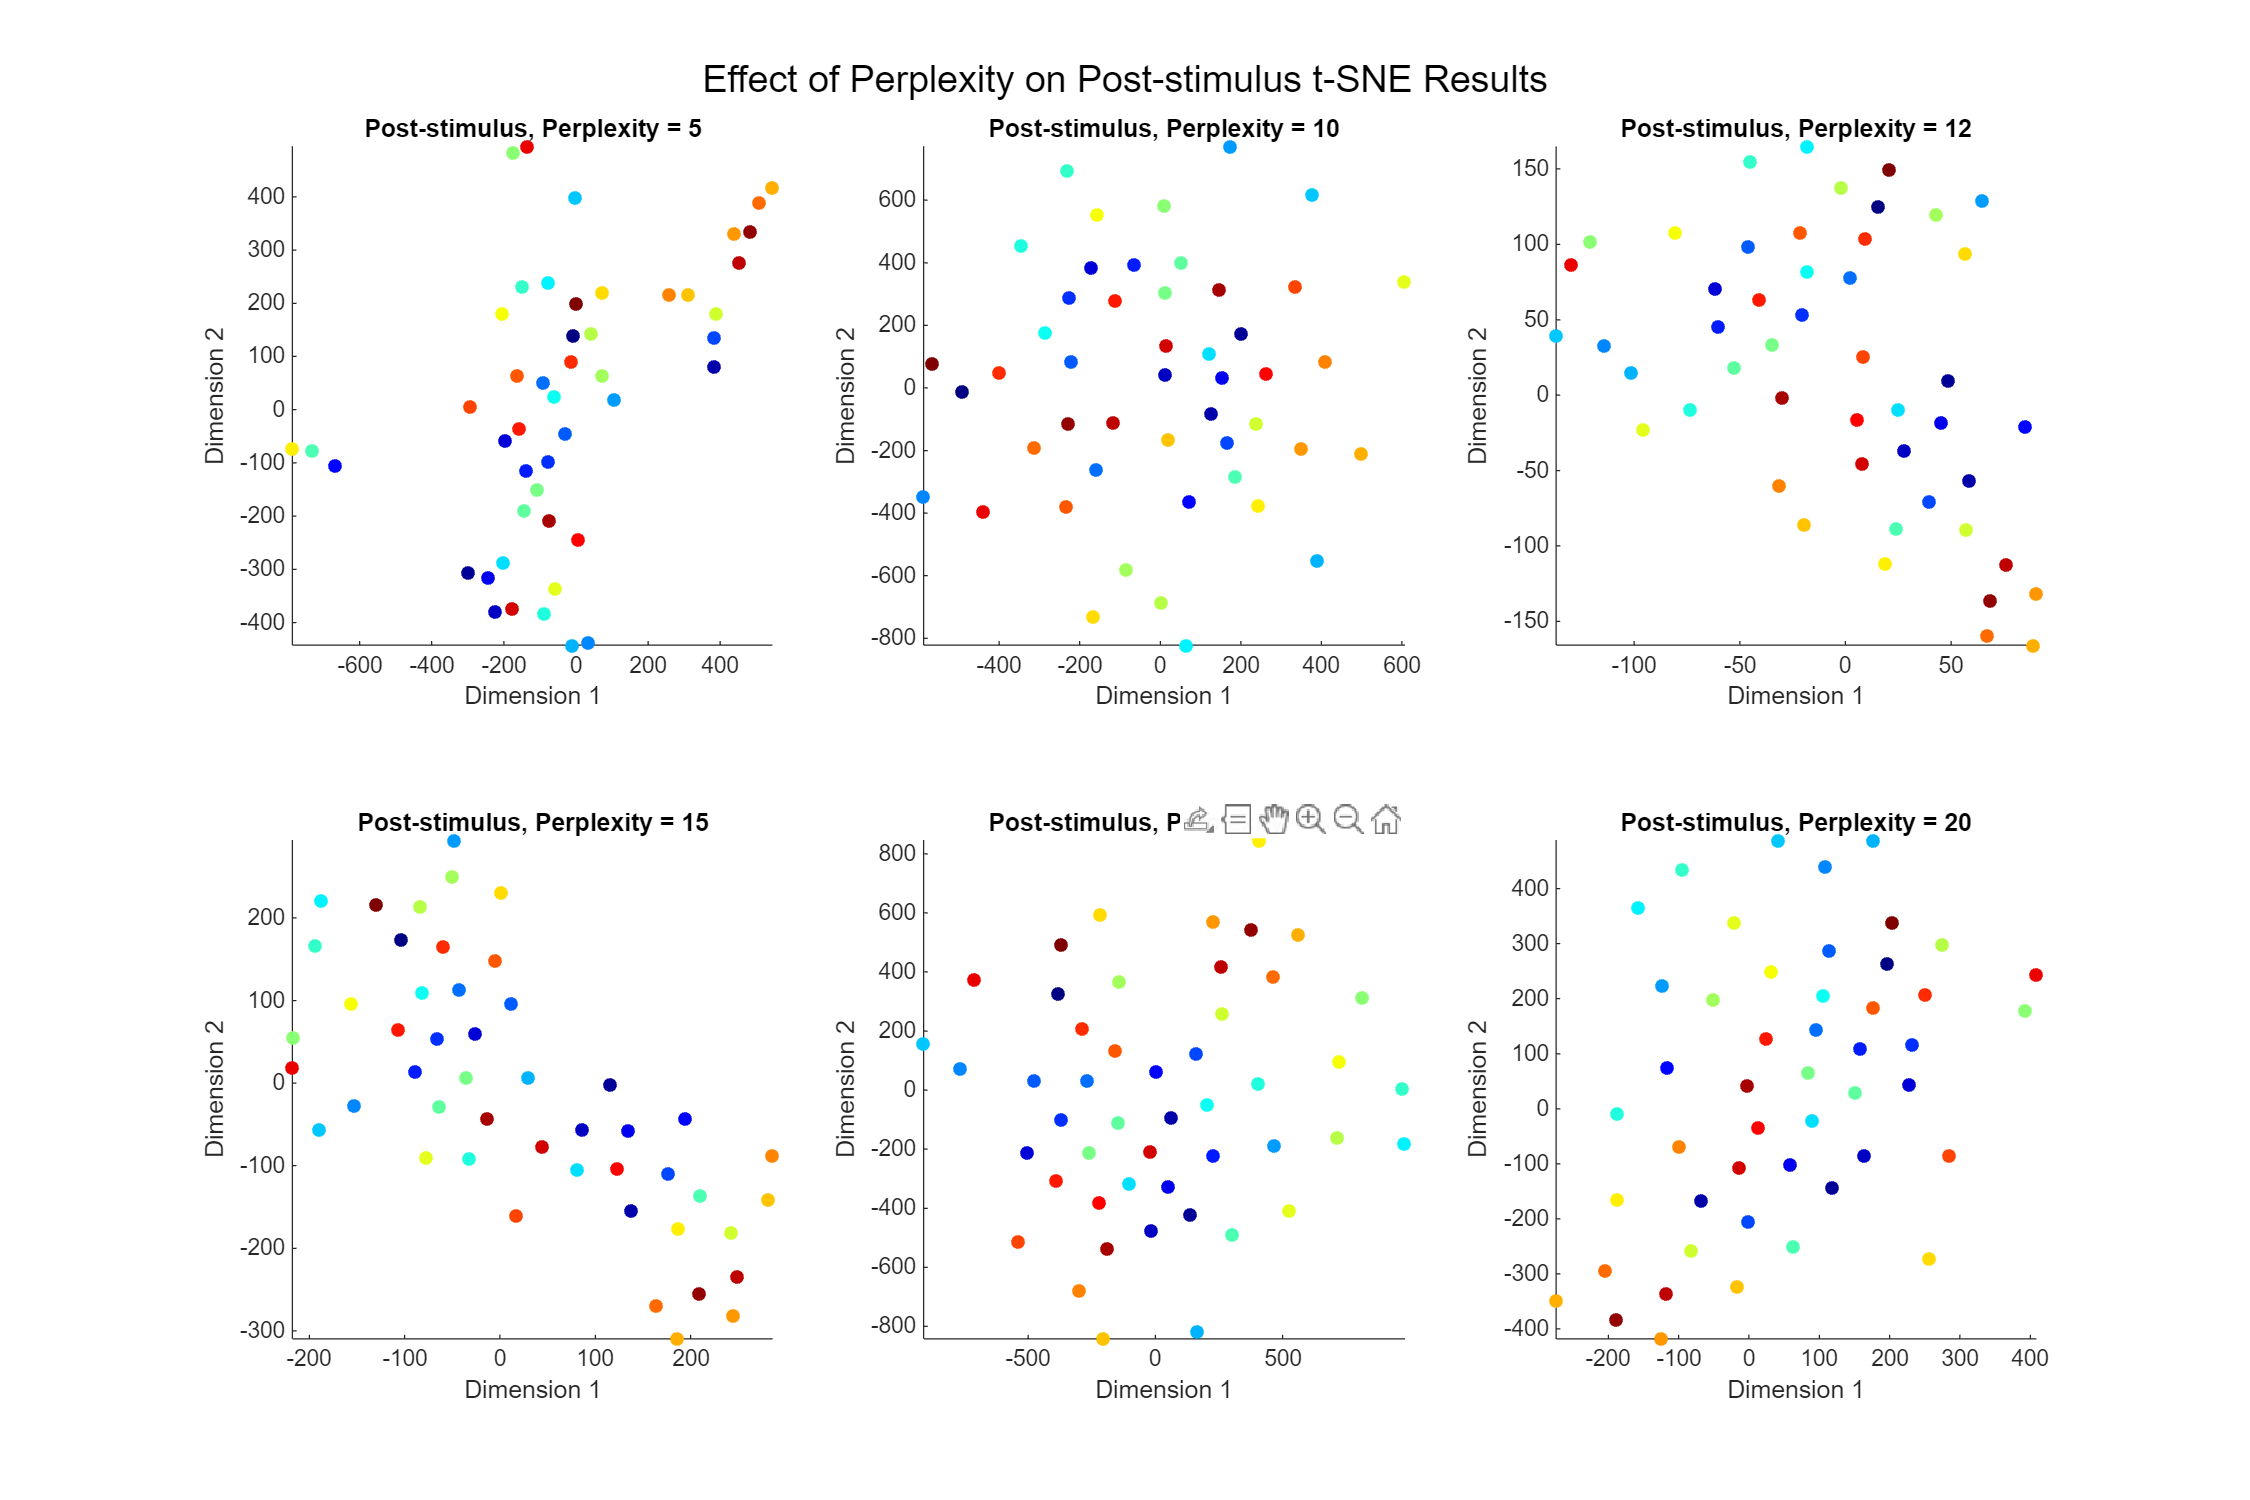


% Create a grid of plots for post-stimulus results
figure('Position', [100, 100, 1200, 800]);
for i = 1:length(perplexity_values)
    subplot(2, 3, i);
    scatter(Y_post_results{i}(:,1), Y_post_results{i}(:,2), 30, 1:size(Y_post_results{i},1), 'filled');
    title(['Post-stimulus, Perplexity = ', num2str(perplexity_values(i))]);
    xlabel('Dimension 1');
    ylabel('Dimension 2');
    colormap(jet);
    axis tight;
end
sgtitle('Effect of Perplexity on Post-stimulus t-SNE Results');

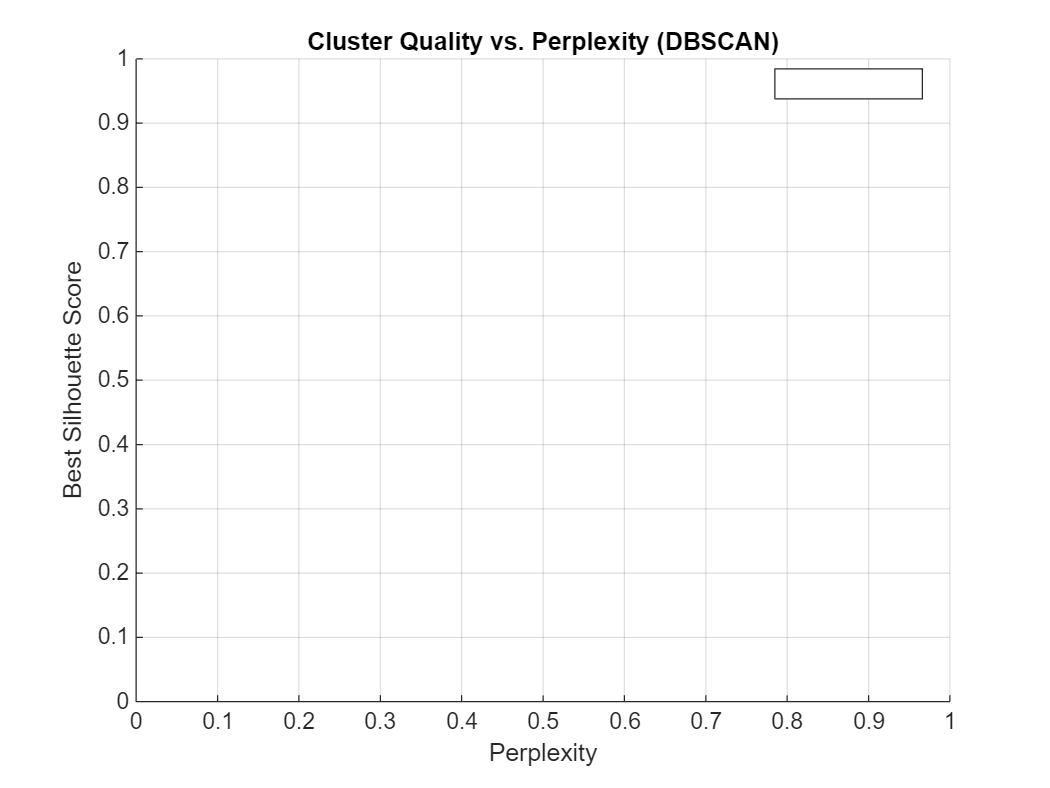

% Alternative cluster quality evaluation using DBSCAN
epsilon_values = [0.5, 1, 2]; % Multiple epsilon values to try
best_silhouette_pre = zeros(length(perplexity_values), 1);
best_silhouette_post = zeros(length(perplexity_values), 1);

for i = 1:length(perplexity_values)
    max_sil_pre = -1;
    max_sil_post = -1;
    
    % Try different epsilon values for DBSCAN
    for eps_val = epsilon_values
        % Pre-stimulus
        try
            % Normalize data before clustering
            data_pre = Y_pre_results{i};
            data_pre = (data_pre - mean(data_pre)) ./ std(data_pre);
            
            idx_pre = dbscan(data_pre, eps_val, 5);
            % Only calculate silhouette if we have more than one cluster 
            % and no noise points (labeled as -1)
            if length(unique(idx_pre)) > 1 && ~any(idx_pre == -1)
                sil_pre = mean(silhouette(data_pre, idx_pre));
                max_sil_pre = max(max_sil_pre, sil_pre);
            end
        catch
            % Skip this epsilon value if an error occurs
        end
        
        % Post-stimulus
        try
            data_post = Y_post_results{i};
            data_post = (data_post - mean(data_post)) ./ std(data_post);
            
            idx_post = dbscan(data_post, eps_val, 5);
            if length(unique(idx_post)) > 1 && ~any(idx_post == -1)
                sil_post = mean(silhouette(data_post, idx_post));
                max_sil_post = max(max_sil_post, sil_post);
            end
        catch
            % Skip this epsilon value if an error occurs
        end
    end
    
    best_silhouette_pre(i) = max_sil_pre;
    best_silhouette_post(i) = max_sil_post;
end

% Plot best silhouette scores
figure;
valid_pre = best_silhouette_pre > 0;
valid_post = best_silhouette_post > 0;

plot(perplexity_values(valid_pre), best_silhouette_pre(valid_pre), 'o-', 'LineWidth', 2, 'DisplayName', 'Pre-stimulus');
hold on;
plot(perplexity_values(valid_post), best_silhouette_post(valid_post), 's-', 'LineWidth', 2, 'DisplayName', 'Post-stimulus');
xlabel('Perplexity');
ylabel('Best Silhouette Score');
title('Cluster Quality vs. Perplexity (DBSCAN)');
legend('Location', 'best');
grid on;

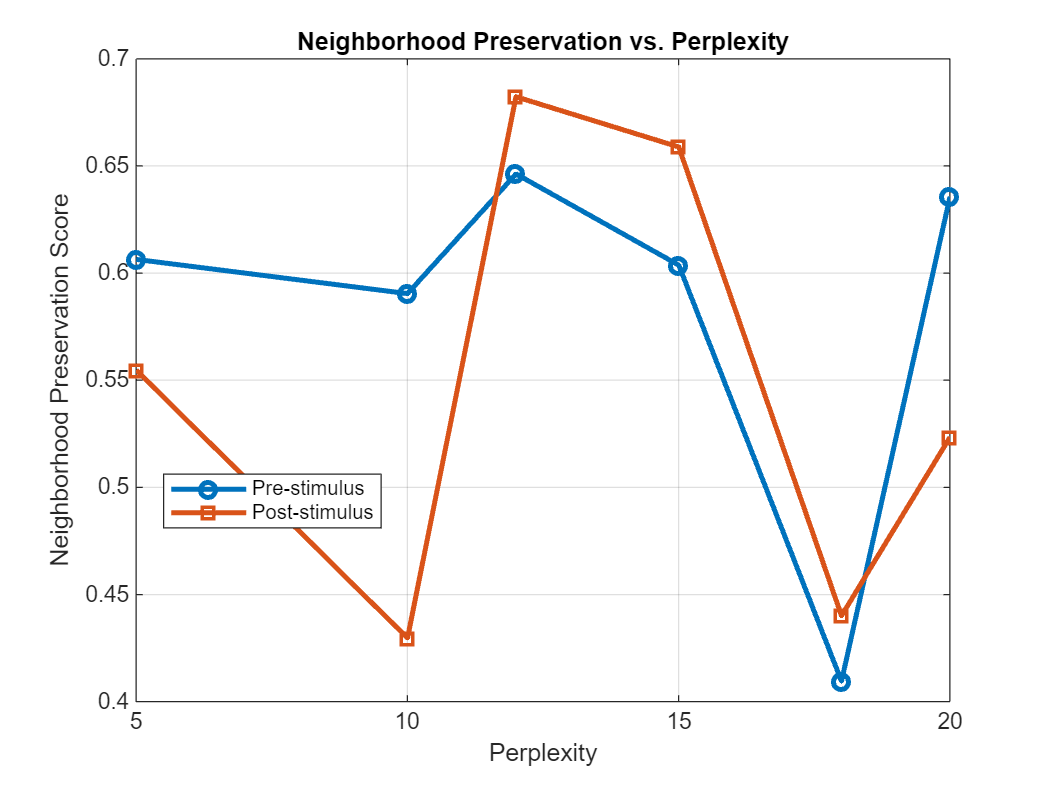

% A simpler approach: evaluate local neighborhood preservation
k_neighbors = 8; % Number of neighbors to consider

% Function to calculate neighborhood preservation
function score = calculate_neighborhood_preservation(orig_data, embedded_data, k)
    % Get the k nearest neighbors in original space
    [~, orig_idx] = pdist2(orig_data, orig_data, 'euclidean', 'Smallest', k+1);
    orig_idx = orig_idx(2:end, :)'; % Remove self and transpose
    
    % Get the k nearest neighbors in embedded space
    [~, emb_idx] = pdist2(embedded_data, embedded_data, 'euclidean', 'Smallest', k+1);
    emb_idx = emb_idx(2:end, :)'; % Remove self and transpose
    
    % Calculate overlap between neighborhoods
    overlap = 0;
    for i = 1:size(orig_data, 1)
        overlap = overlap + length(intersect(orig_idx(i,:), emb_idx(i,:)));
    end
    
    % Return average percentage of preserved neighbors
    score = overlap / (k * size(orig_data, 1));
end

% Calculate neighborhood preservation for each perplexity
neighborhood_scores_pre = zeros(length(perplexity_values), 1);
neighborhood_scores_post = zeros(length(perplexity_values), 1);

for i = 1:length(perplexity_values)
    neighborhood_scores_pre(i) = calculate_neighborhood_preservation(trial_factors_pre, Y_pre_results{i}, k_neighbors);
    neighborhood_scores_post(i) = calculate_neighborhood_preservation(trial_factors_post, Y_post_results{i}, k_neighbors);
end

% Plot neighborhood preservation scores
figure;
plot(perplexity_values, neighborhood_scores_pre, 'o-', 'LineWidth', 2, 'DisplayName', 'Pre-stimulus');
hold on;
plot(perplexity_values, neighborhood_scores_post, 's-', 'LineWidth', 2, 'DisplayName', 'Post-stimulus');
xlabel('Perplexity');
ylabel('Neighborhood Preservation Score');
title('Neighborhood Preservation vs. Perplexity');
legend('Location', 'best');
grid on;